# Antarctic exposure age recalculation code

This code recalculates the exposure age of different sites in Antarctica and generates various plots to visualize the difference.

The code requires that a datafile exists which has the ages stored in it that can be used for plotting. The ages are calculated from the expage calcualtor.

### Setup workspace and Load Data

%CAUTION: Uncomment this if it is necessary to clear the workspace, but leave
%commented if there are other variables that you don't want cleared
%clear, clc, close all

warning('off')


% orig_age: Age from ICE-D
% calib_age: Expage ages using PR 13.38
% fit_age: Ages from ICE-D after calibrating to the CRONUS-A production rate
% in the online calcualtors to fit this calculator to the expage calculator
% check_age: Expage ages using PR 11.21 to check for calculator consistensy
% pub_age: Published age
% fit_resid: calib_age-fit_age
% check_resid: check_age-orig_age
% age_offset: calib_age-pub_age (except for ase because of incomplete
% published ages in which case it is calib_age-orig_age
load('dml.mat')
load('las.mat')
load('ase.mat')
load('tam.mat')
load('supporting_data.mat')

### Plot the main discussion figure

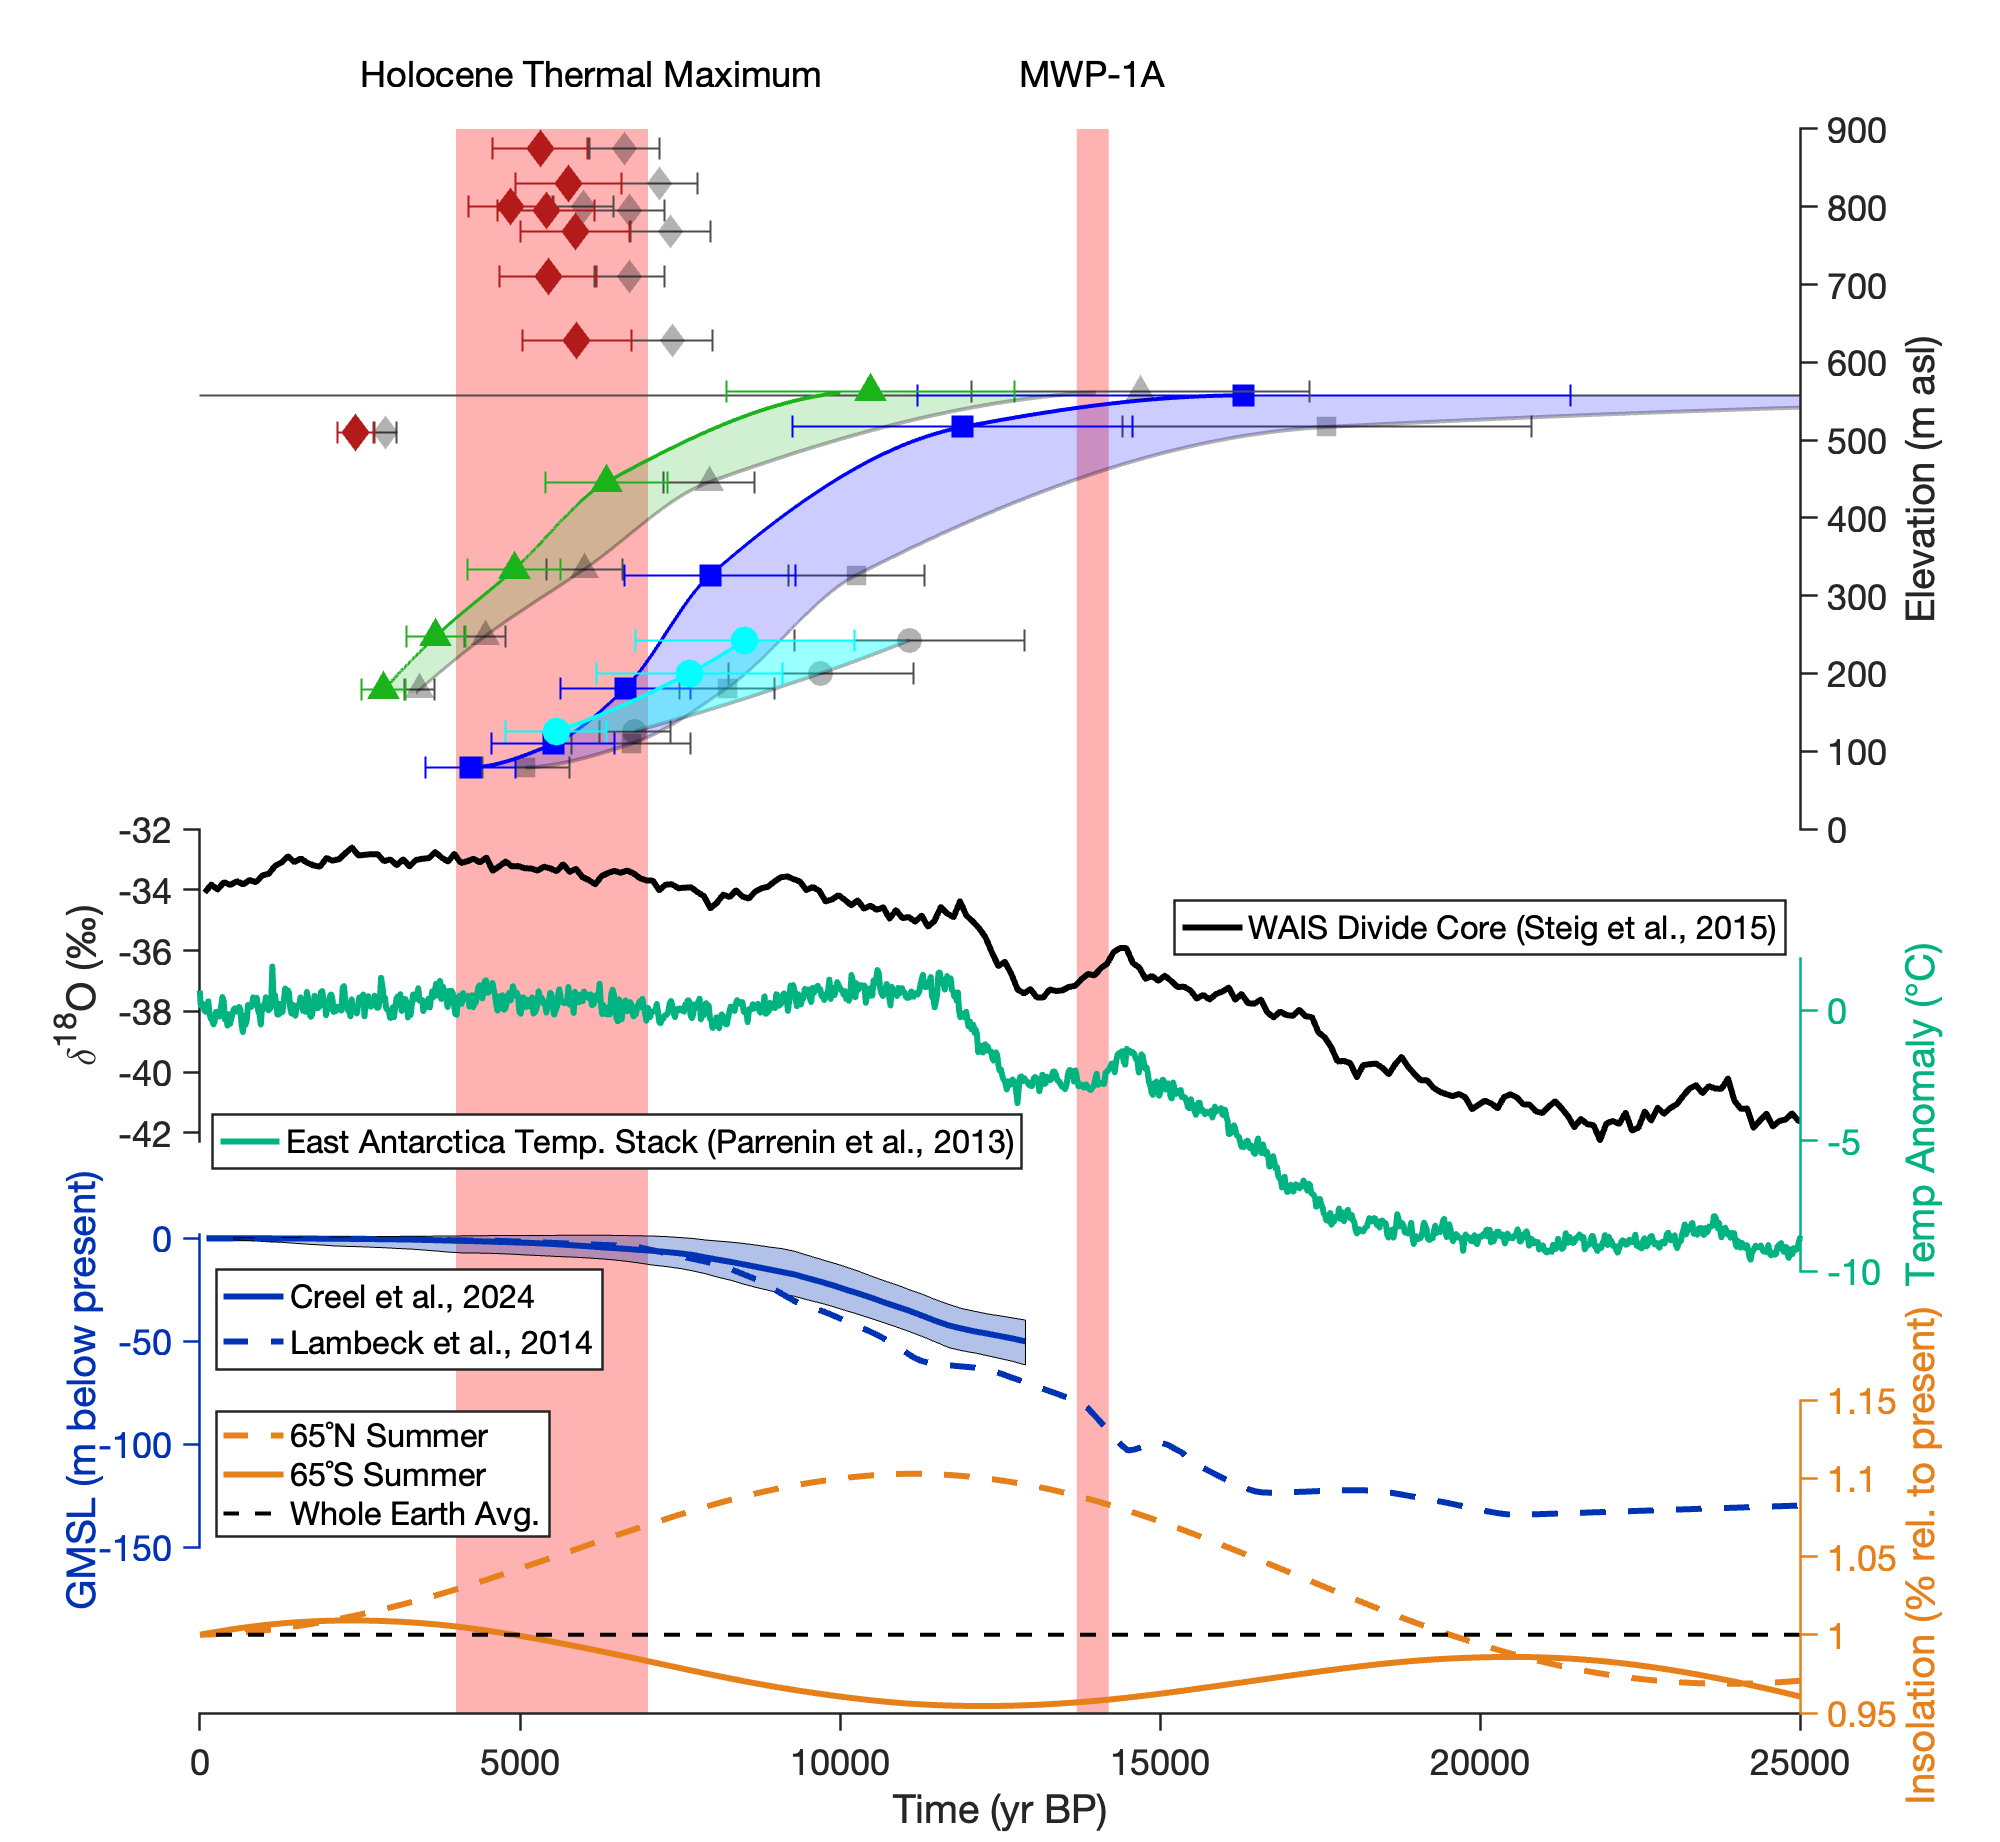

% Set figure settings
set(0,'DefaultFigureVisible','on');
set(0,'DefaultFigureWindowStyle','normal');   % not docked

% Initialize figure
figure('Units','pixels','Position',[100 100 1000 1000],'Color','w');

% Set subplot locations manually for better plotting
fig1.left = 0.1; fig1.width = 0.8; fig1.h = 0.17;
fig1.b1 = 0.98 - 0.43;
fig1.b2 = fig1.b1 - (fig1.h + 0);
fig1.b3 = fig1.b2 - (fig1.h - 0.1);
fig1.b4 = fig1.b3 - (fig1.h - 0.02);
fig1.b5 = fig1.b4 - (fig1.h - 0.08);

% Initialize axes based on subplot locations
ax.ax1 = axes('Position',[fig1.left fig1.b1 fig1.width 0.38], 'Box','off', 'Layer','top');
ax.ax2 = axes('Position',[fig1.left fig1.b2 fig1.width fig1.h], 'Box','off', 'Layer','top');
ax.ax3 = axes('Position',[fig1.left fig1.b3 fig1.width fig1.h], 'Box','off', 'Layer','top');
ax.ax4 = axes('Position',[fig1.left fig1.b4 fig1.width fig1.h], 'Box','off', 'Layer','top');
ax.ax5 = axes('Position',[fig1.left fig1.b5 fig1.width fig1.h], 'Box','off', 'Layer','top');

% Create and array of axes and hold on
axes_arr = [ax.ax1 ax.ax2 ax.ax3 ax.ax4 ax.ax5];
hold(axes_arr, 'on')



% - ax1 -
tam.tam_subset_samples = [1, 2, 12, 13, 14, 15];%, 26];
tam.avg_subset_samples = [18, 20, 22];%, 23];
ase.ase_subset_samples = [3, 17, 22, 27, 29];
for i = tam.tam_subset_samples
    errorbar(ax.ax1, tam.orig_age(i), tam.elev(i), ...
            tam.orig_unc(i), tam.orig_unc(i), ...
            'horizontal','LineStyle','none', 'LineWidth', 1, 'Color', [0.3 0.3 0.3 0.4], 'CapSize',10);
    scatter(ax.ax1, tam.orig_age(i),  tam.elev(i), 160, 'k', 'filled', 'Marker','s', 'MarkerFaceAlpha',0.3);
    errorbar(ax.ax1, tam.calib_age(i), tam.elev(i), ...
            tam.calib_unc(i), tam.calib_unc(i), ...
            'horizontal','LineStyle','none', 'LineWidth', 1, 'Color','b', 'CapSize',10);
    scatter(ax.ax1, tam.calib_age(i), tam.elev(i), 200, 'b', 'filled', 'Marker','s', 'DisplayName','Trans-Antarctic Mountains');
end

% Plot the pchip spline for the TAMs
splines.tam_spline.x_calib = [sort(tam.calib_age(tam.tam_subset_samples),'descend')];
splines.tam_spline.y = [sort(tam.elev(tam.tam_subset_samples), 'descend')];
splines.tam_spline.pp_calib = pchip(splines.tam_spline.x_calib, splines.tam_spline.y);
splines.tam_spline.xx_calib= linspace(4223, 16308, 10000);
plot(ax.ax1, splines.tam_spline.xx_calib, ppval(splines.tam_spline.pp_calib, splines.tam_spline.xx_calib), 'LineWidth', 2, 'Color','b');
splines.tam_spline.yy_calib = ppval(splines.tam_spline.pp_calib, splines.tam_spline.xx_calib);

splines.tam_spline.x_orig = [sort(tam.orig_age(tam.tam_subset_samples),'descend')];
splines.tam_spline.pp_orig = pchip(splines.tam_spline.x_orig, splines.tam_spline.y);
splines.tam_spline.xx_orig = linspace(5089, 38061, 10000);
plot(ax.ax1, splines.tam_spline.xx_orig, ppval(splines.tam_spline.pp_orig, splines.tam_spline.xx_orig), 'LineWidth', 2, 'Color', [0 0 0 0.3]);
splines.tam_spline.yy_orig = ppval(splines.tam_spline.pp_orig, splines.tam_spline.xx_orig);

uistack(fill(ax.ax1, [splines.tam_spline.xx_calib(:); flipud(splines.tam_spline.xx_orig(:))], ...
    [splines.tam_spline.yy_calib(:); flipud(splines.tam_spline.yy_orig(:))], 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'none'), 'top');


for i = tam.avg_subset_samples
    errorbar(ax.ax1, tam.orig_age(i), tam.elev(i), ...
            tam.orig_unc(i), tam.orig_unc(i), ...
            'horizontal','LineStyle','none', 'LineWidth', 1, 'Color', [0.3 0.3 0.3 0.4], 'CapSize',10);
    scatter(ax.ax1, tam.orig_age(i),  tam.elev(i), 160, 'k', 'filled', 'Marker','o', 'MarkerFaceAlpha',0.3);
    errorbar(ax.ax1, tam.calib_age(i), tam.elev(i), ...
            tam.calib_unc(i), tam.calib_unc(i), ...
            'horizontal','LineStyle','none', 'LineWidth', 1, 'Color','c', 'CapSize',10);
    scatter(ax.ax1, tam.calib_age(i), tam.elev(i), 200, 'c', 'filled', 'Marker','o', 'DisplayName','Trans-Antarctic Mountains');
end

% Plot the pchip spline for the Aviator Glacier
splines.avg_spline.x_calib = [sort(tam.calib_age(tam.avg_subset_samples),'descend')];
splines.avg_spline.y = [sort(tam.elev(tam.avg_subset_samples), 'descend')];
splines.avg_spline.pp_calib = pchip(splines.avg_spline.x_calib, splines.avg_spline.y);
splines.avg_spline.xx_calib= linspace(5568, 8514, 10000);
plot(ax.ax1, splines.avg_spline.xx_calib, ppval(splines.avg_spline.pp_calib, splines.avg_spline.xx_calib), 'LineWidth', 2, 'Color','c');
splines.avg_spline.yy_calib = ppval(splines.avg_spline.pp_calib, splines.avg_spline.xx_calib);

splines.avg_spline.x_orig = [sort(tam.orig_age(tam.avg_subset_samples),'descend')];
splines.avg_spline.pp_orig = pchip(splines.avg_spline.x_orig, splines.avg_spline.y);
splines.avg_spline.xx_orig = linspace(6793, 11085, 10000);
plot(ax.ax1, splines.avg_spline.xx_orig, ppval(splines.avg_spline.pp_orig, splines.avg_spline.xx_orig), 'LineWidth', 2, 'Color', [0 0 0 0.3]);
splines.avg_spline.yy_orig = ppval(splines.avg_spline.pp_orig, splines.avg_spline.xx_orig);

uistack(fill(ax.ax1, [splines.avg_spline.xx_calib(:); flipud(splines.avg_spline.xx_orig(:))], [splines.avg_spline.yy_calib(:); flipud(splines.avg_spline.yy_orig(:))], 'c', 'FaceAlpha', 0.4, 'EdgeColor', 'none'), 'top');


for i = ase.ase_subset_samples
    errorbar(ax.ax1, ase.orig_age(i), ase.elev(i), ...
        ase.orig_unc(i), ase.orig_unc(i), ...
        'horizontal','LineStyle','none', 'LineWidth', 1, 'Color', [0.3 0.3 0.3 0.4], 'CapSize',10);
    scatter(ax.ax1, ase.orig_age(i),  ase.elev(i), 160, 'k', 'filled', 'Marker','^', 'MarkerFaceAlpha',0.3);
    errorbar(ax.ax1, ase.calib_age(i), ase.elev(i), ...
        ase.calib_unc(i), ase.calib_unc(i), ...
        'horizontal','LineStyle','none', 'LineWidth', 1, 'Color',[0.1 0.7 0.1], 'CapSize',10);
    scatter(ax.ax1, ase.calib_age(i), ase.elev(i), 200, [0.1 0.7 0.1], 'filled', ...
        'Marker', '^', 'DisplayName','Trans-Antarctic Mountains');
end

% Plot the pchip spline for the ASE
splines.ase_spline.x_calib = [sort(ase.calib_age(ase.ase_subset_samples),'descend')];
splines.ase_spline.y = [sort(ase.elev(ase.ase_subset_samples), 'descend')];
splines.ase_spline.pp_calib = pchip(splines.ase_spline.x_calib, splines.ase_spline.y);
splines.ase_spline.xx_calib= linspace(2821, 10004, 10000);
plot(ax.ax1, splines.ase_spline.xx_calib, ppval(splines.ase_spline.pp_calib, splines.ase_spline.xx_calib), 'LineWidth', 2, 'Color',[0.1 0.7 0.1]);
splines.ase_spline.yy_calib = ppval(splines.ase_spline.pp_calib, splines.ase_spline.xx_calib);

splines.ase_spline.x_orig = [sort(ase.orig_age(ase.ase_subset_samples),'descend')];
splines.ase_spline.pp_orig = pchip(splines.ase_spline.x_orig, splines.ase_spline.y);
splines.ase_spline.xx_orig = linspace(3376, 13996, 10000);
plot(ax.ax1, splines.ase_spline.xx_orig, ppval(splines.ase_spline.pp_orig, splines.ase_spline.xx_orig), 'LineWidth', 2, 'Color', [0 0 0 0.3]);
splines.ase_spline.yy_orig = ppval(splines.ase_spline.pp_orig, splines.ase_spline.xx_orig);

uistack(fill(ax.ax1, [splines.ase_spline.xx_calib(:); flipud(splines.ase_spline.xx_orig(:))], [splines.ase_spline.yy_calib(:); flipud(splines.ase_spline.yy_orig(:))], [0.1 0.7 0.1], 'FaceAlpha', 0.2, 'EdgeColor', 'none'), 'bottom');

errorbar(ax.ax1, las.orig_age, las.elev, ...
        las.orig_unc, las.orig_unc, ...
        'horizontal','LineStyle','none', 'LineWidth', 1, 'Color', [0.3 0.3 0.3 0.4], 'CapSize',10);
scatter(ax.ax1, las.orig_age,  las.elev, 160, 'k', 'filled', 'Marker','d', 'MarkerFaceAlpha',0.3);
errorbar(ax.ax1, las.calib_age, las.elev, ...
        las.calib_unc, las.calib_unc, ...
        'horizontal','LineStyle','none', 'LineWidth', 1, 'Color',[0.7 0.1 0.1], 'CapSize',10);
scatter(ax.ax1, las.calib_age, las.elev, 200, [0.7 0.1 0.1], 'filled', 'Marker', 'd', 'DisplayName','Trans-Antarctic Mountains');

ylabel(ax.ax1,'Elevation (m asl)');


% - ax2 -
% δ18O on ax2
cla(ax.ax2);
plot(ax.ax2, clim_data.waisO18.age, clim_data.waisO18.oxy, 'k-', 'LineWidth',3, 'DisplayName', 'WAIS Divide Core (Steig et al., 2015)');
ylabel(ax.ax2,'\delta^{18}O (‰)','Interpreter','tex');
set(ax.ax2,'YAxisLocation','left','YLim',[-42.3 -32], ...
        'TickDir','out','LineWidth',1.25,'FontName','Helvetica', ...
        'Color','none','PositionConstraint','innerposition');
legend(ax.ax2, 'location', [0.58675,0.483323281907433,0.3055,0.027173913043479])


% - ax3 -
ax.ax3_1 = plot(ax.ax3, clim_data.EATA.age, clim_data.EATA.TA, 'Color',[0 0.7 0.5], 'LineWidth',3, 'DisplayName', 'East Antarctica Temp. Stack (Parrenin et al., 2013)');
ylim(ax.ax3, [-10 2]);
ax.ax3.YColor = [0 0.7 0.5];  % color of y-axis and ticks
ax.ax3.YLabel.Color = [0 0.7 0.5];  % color of the y-axis label
ylabel(ax.ax3,'Temp Anomaly (°C)'); yticks([-10 -8 -6 -4 -2 0 1]);
legend(ax.ax3, [ax.ax3_1], 'location', [0.106,0.366847826086956,0.405,0.027173913043478])


% - ax4 -
ax.ax4_1 = plot(ax.ax4, clim_data.creelSLR.age, clim_data.creelSLR.mid, 'Color',[0 0.2 0.7], 'LineWidth', 3, 'DisplayName', 'Creel et al., 2024');
fill(ax.ax4, [clim_data.creelSLR.age; flipud(clim_data.creelSLR.age)], [clim_data.creelSLR.lowunc; flipud(clim_data.creelSLR.highunc)], [0 0.2 0.7], 'FaceAlpha', 0.3)
ax.ax4_2 = plot(ax.ax4, clim_data.lambeckSLR.age, clim_data.lambeckSLR.SLR, 'Color',[0 0.2 0.7], 'LineWidth', 3, 'LineStyle', '--','DisplayName', 'Lambeck et al., 2014');
ylabel(ax.ax4,'GMSL (m below present)');
ylim(ax.ax4,[-150 2]);
ax.ax4.YColor = [0 0.2 0.7];  % color of y-axis and ticks
ax.ax4.YLabel.Color = [0 0.2 0.7];  % color of the y-axis label
yticks([-150 -100 -50 0])
legend(ax.ax4, [ax.ax4_1 ax.ax4_2], 'location', [0.108166666666667,0.258734247006931,0.193,0.050212665406427])


% - ax5 -
plot(ax.ax5, clim_data.solin65n.age, clim_data.solin65n.insolref, 'LineWidth',3, 'Color', [0.9 0.5 0.1], 'LineStyle', '--', 'DisplayName', '65˚N Summer');
plot(ax.ax5, clim_data.solin65s.age, clim_data.solin65s.insolref, 'LineWidth',3, 'Color', [0.9 0.5 0.1], 'DisplayName', '65˚S Summer');
plot(ax.ax5, clim_data.solinavg.age, clim_data.solinavg.insolref, 'k--', 'LineWidth',2, 'DisplayName', 'Whole Earth Avg.');
ylabel(ax.ax5,'Insolation (% rel. to present)', 'HorizontalAlignment', 'center');
ylim(ax.ax5,[0.95 1.15]);
yticks([0.95 1 1.05 1.1 1.15])
ax.ax5.YColor = [0.9 0.5 0.1];  % color of y-axis and ticks
ax.ax5.YLabel.Color = [0.9 0.5 0.1];  % color of the y-axis label
xticks([0 5000 10000 15000 20000 25000])
ax.ax5.XAxis.Exponent = 0; xlabel(ax.ax5,'Time (yr BP)');
legend(ax.ax5, 'location', 'northwest')


% Linkaxes and x-axis formatting
linkaxes(axes_arr,'x');
set([ax.ax1 ax.ax2 ax.ax3 ax.ax4 ax.ax5], 'FontSize',18, 'FontName','Helvetica', ...
    'TickDir','out', 'LineWidth',1.25, 'Color','none');
set([ax.ax1 ax.ax2 ax.ax3 ax.ax4], 'XColor','none','XTick',[]);
xlim([0 25000]);

% Set y-axis sides to alternate for spacing
set([ax.ax1 ax.ax3 ax.ax5],'YAxisLocation','right');
set([ax.ax2 ax.ax4],'YAxisLocation','left');

% y-label spacing solves additional axis labelling overlap issues
for ax100 = [ax.ax2 ax.ax4]
    ax100.YLabel.Units = 'normalized'; fig1.p = ax100.YLabel.Position; fig1.p(1) = -0.06; ax100.YLabel.Position = fig1.p;
end
for ax100 = [ax.ax1 ax.ax3 ax.ax5]
    ax100.YLabel.Units = 'normalized'; fig1.p = ax100.YLabel.Position; fig1.p(1) = 1.06;  ax100.YLabel.Position = fig1.p;
end

% Set axis for multipanel overlay data
fig1.Ytop = ax.ax1.Position(2) + ax.ax1.Position(4);   % top of top panel
fig1.Ybot = ax.ax5.Position(2);                     % bottom of lowest panel
bandAx = axes('Position',[fig1.left fig1.Ybot fig1.width (fig1.Ytop - fig1.Ybot)], ...
    'Color','none','HitTest','off','HandleVisibility','off', ...
    'XLim',[0 25000],'YLim',[0 1], 'XTick',[], 'YTick',[], ...
    'XColor','none','YColor','none','Layer','bottom');

% Assign the size of multipanel bands
% y0,y1 are fractions of the bandAx height (0 = bottom, 1 = top)
fig1.span_all = [0 1];
fig1.bands = [ 4000  7000;
         13700 14200];
fig1.cols  = [1 0 0; 1 0 0];
fig1.alpha_main = 0.30;

for b = 1:size(fig1.bands,1)
    fig1.x0 = fig1.bands(b,1); fig1.x1 = fig1.bands(b,2);
    fig1.y0y1 = fig1.span_all;
    patch(bandAx,[fig1.x0 fig1.x1 fig1.x1 fig1.x0],[fig1.y0y1(1) fig1.y0y1(1) fig1.y0y1(2) fig1.y0y1(2)], ...
          fig1.cols(b,:), 'FaceAlpha', fig1.alpha_main, 'EdgeColor','none');
end

% keep behind data and lock x with the other axes
linkaxes([axes_arr bandAx],'x');
% move the entire background axis behind all other axes
uistack(bandAx, 'bottom');

% labels
fig1.yl1 = ylim(ax.ax1);
text(ax.ax1,12800,fig1.yl1(2)*1.08,'MWP-1A','FontSize',18,'FontName','Helvetica','Clipping','off');
text(ax.ax1, 2500,fig1.yl1(2)*1.08,'Holocene Thermal Maximum','FontSize',18,'FontName','Helvetica','Clipping','off');


fig = gcf;

%Turn on to save a high-resolution figure
%print(fig, 'finaldiscussionfigure.png', '-dpng', '-r600')

clear fig fig1 ax ax100 axes_arr b i bandAx

### Calculate and Plot Thinning Rates

Three blocks of code for each of the three locations we calculate thinning profiles calculate the derivative using "fnder" of the thinning profile calculated and plotted in the above code. Then using ppval, a continuous dataset is generated based on the piecewise polynomial derivative. This process is repeated for the calibrated values and then for the original value and for all three sites. The data is plotted at the bottom of the code. 

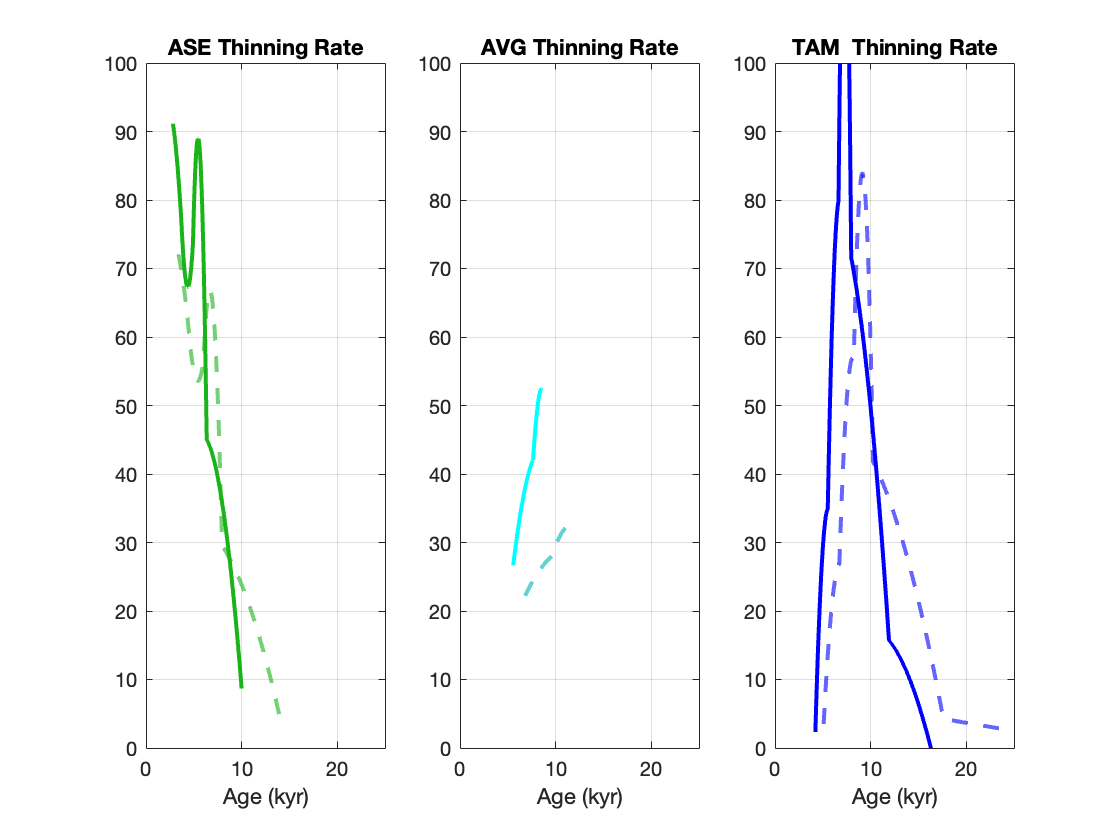

% ASE
splines.ase_spline.pp_calib_deriv = fnder(splines.ase_spline.pp_calib);
splines.ase_spline.slope_calib = ppval(splines.ase_spline.pp_calib_deriv, ...
    splines.ase_spline.xx_calib) * 1000;

splines.ase_spline.pp_orig_deriv = fnder(splines.ase_spline.pp_orig);
splines.ase_spline.slope_orig = ppval(splines.ase_spline.pp_orig_deriv, ...
    splines.ase_spline.xx_orig) * 1000;



% AVG
splines.avg_spline.pp_calib_deriv = fnder(splines.avg_spline.pp_calib);
splines.avg_spline.slope_calib = ppval(splines.avg_spline.pp_calib_deriv, ...
    splines.avg_spline.xx_calib) * 1000;

splines.avg_spline.pp_orig_deriv = fnder(splines.avg_spline.pp_orig);
splines.avg_spline.slope_orig = ppval(splines.avg_spline.pp_orig_deriv, ...
    splines.avg_spline.xx_orig) * 1000;



% TAM
splines.tam_spline.pp_calib_deriv = fnder(splines.tam_spline.pp_calib);
splines.tam_spline.slope_calib = ppval(splines.tam_spline.pp_calib_deriv, ...
    splines.tam_spline.xx_calib) * 1000;

splines.tam_spline.pp_orig_deriv = fnder(splines.tam_spline.pp_orig);
splines.tam_spline.slope_orig = ppval(splines.tam_spline.pp_orig_deriv, ...
    splines.tam_spline.xx_orig) * 1000;




% Plotting
% Set figure settings
set(0,'DefaultFigureVisible','on');
set(0,'DefaultFigureWindowStyle','normal');   % not docked

figure('Color','w');


% ASE
subplot(1,3,1); hold on; box on;
plot(splines.ase_spline.xx_calib/1000, splines.ase_spline.slope_calib, ...
    'LineWidth',2, 'Color',[0.1 0.7 0.1]);
plot(splines.ase_spline.xx_orig/1000,  splines.ase_spline.slope_orig,  ...
    '--', 'LineWidth',2, 'Color',[0.1 0.7 0.1 0.6]);

xlim([0 25]); ylim([0 100]);
xlabel('Age (kyr)');
ax = gca;
ax.XAxis.Exponent = 0;
title('ASE Thinning Rate');
grid on;


% AVG
subplot(1,3,2); hold on; box on;
plot(splines.avg_spline.xx_calib/1000, splines.avg_spline.slope_calib, ...
    'LineWidth',2, 'Color','c');
plot(splines.avg_spline.xx_orig/1000,  splines.avg_spline.slope_orig,  ...
    '--', 'LineWidth',2, 'Color',[0 0.7 0.7 0.6]);

xlim([0 25]); ylim([0 100]);
ax = gca;
ax.XAxis.Exponent = 0;
xlabel('Age (kyr)');
title('AVG Thinning Rate');
grid on;


% TAM
subplot(1,3,3); hold on; box on;
plot(splines.tam_spline.xx_calib/1000, splines.tam_spline.slope_calib, ...
    'LineWidth',2, 'Color','b');
plot(splines.tam_spline.xx_orig/1000,  splines.tam_spline.slope_orig, ...
    '--', 'LineWidth',2, 'Color',[0 0 1 0.6]);

xlim([0 25]); ylim([0 100]);
ax = gca;
ax.XAxis.Exponent = 0;
xlabel('Age (kyr)');
title('TAM  Thinning Rate');
grid on;


clear ax

### Plot Lassiter Coast Data

Data from Johnson et al., 2019 and re-analyzed in Nichols et al., 2019 in the context of the broader Weddell Sea

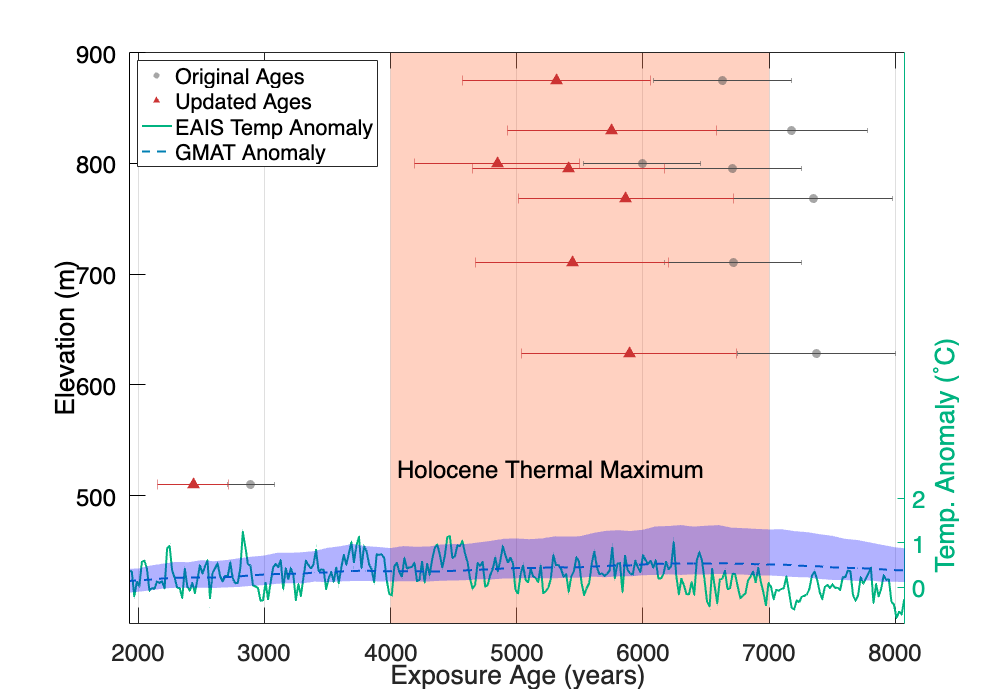

figure;
hold on;
yyaxis left
fill([4000 7000 7000 4000], [300 300 900 900], [1 0.4 0.2], ...
     'EdgeColor', 'none', 'FaceAlpha', 0.3);  % HCM

% Error bars
laorig_err = errorbar(las.orig_age, las.elev, las.orig_unc, las.orig_unc, ...
    'horizontal', 'LineStyle', 'none', 'Color', [0.3 0.3 0.3 0.4], ...
    'CapSize', 5);
lanew_err = errorbar(las.calib_age, las.elev, las.calib_unc, las.calib_unc, ...
    'horizontal', 'LineStyle', 'none', 'Color', [0.8 0.2 0.2 0.4], ...
    'CapSize', 10);

% Markers
laorig = scatter(las.orig_age, las.elev, 80, 'o', ...
    'MarkerEdgeColor', 'none', ...
    'MarkerFaceColor', [0.3 0.3 0.3], ...
    'MarkerFaceAlpha', 0.5, ...
    'MarkerEdgeAlpha', 0.5, ...
    'DisplayName', 'Original Ages');

lanew = scatter(las.calib_age, las.elev, 120, '^', ...
    'MarkerEdgeColor', 'none', ...
    'MarkerFaceColor', [0.8 0.2 0.2], ...
    'MarkerFaceAlpha', 1, ...
    'MarkerEdgeAlpha', 1, ...
    'DisplayName', 'Updated Ages');

plot(clim_data.EATA.age, clim_data.EATA.TA);

% Axes and labels
xlabel('Exposure Age (years)');
ylabel('Elevation (m)');

grid on;
xlim([min([las.orig_age; las.calib_age]) - 500, ...
      max([las.orig_age; las.calib_age]) + 700]);
ylim([min(las.elev)-125, max(las.elev)+25]);
yticks([500 600 700 800 900])
set(gca, 'FontSize', 24, 'FontName', 'Helvetica', 'Box', 'on', 'YColor', [0 0 0], 'YGrid', 'off');
text(4050, 525, 'Holocene Thermal Maximum', 'FontSize', 24, 'FontName', 'Helvetica')

yyaxis right
hold on
TA = plot(clim_data.EATA.age, clim_data.EATA.TA, 'LineWidth', 2, 'Color', [0 0.7 0.5], 'MarkerFaceColor', 'none', ...
    'MarkerEdgeColor', 'none');
TAmed = plot(clim_data.SurfTemp.age, clim_data.SurfTemp.globalmed, 'LineWidth', 2, 'Color', [0 0.5 0.7], 'MarkerFaceColor', 'none', ...
    'MarkerEdgeColor', 'none');
TAlow = fill([clim_data.SurfTemp.age; flipud(clim_data.SurfTemp.age)], [clim_data.SurfTemp.globallowconf; flipud(clim_data.SurfTemp.globalhighconf)], 'b', 'EdgeColor', 'none', 'FaceAlpha', 0.3);
ylim([-0.8 12])
ylabel('Temp. Anomaly (˚C)', 'HorizontalAlignment','right')
yticks([-1 0 1 2])
set(gca, 'YColor', [0 0.7 0.5]);


TA = legend([laorig, lanew, TA, TAmed], {'Original Ages', 'Updated Ages', 'EAIS Temp Anomaly', 'GMAT Anomaly'}, 'Location', 'northwest');
%title('Lassiter Coast');
set(gcf,'Position',[100 100 1000 700]);
set(gca, 'FontSize', 24, 'FontName', 'Helvetica', 'Box', 'on','YGrid', 'off');
hold off;

fig = gcf;
%Turn on to save a high-resolution figure
%print(fig, 'lassitercoast.png', '-dpng', '-r600')

hold off;

clear lanew lanew_err laorig laorig_err TA TAmed TAlow fig

### Plot Residuals

Plot the residuals to compare the two calculators used the expage and online exposure calcualator from Balco et al., 2008

#### Plot residuals for Lassiter Coast

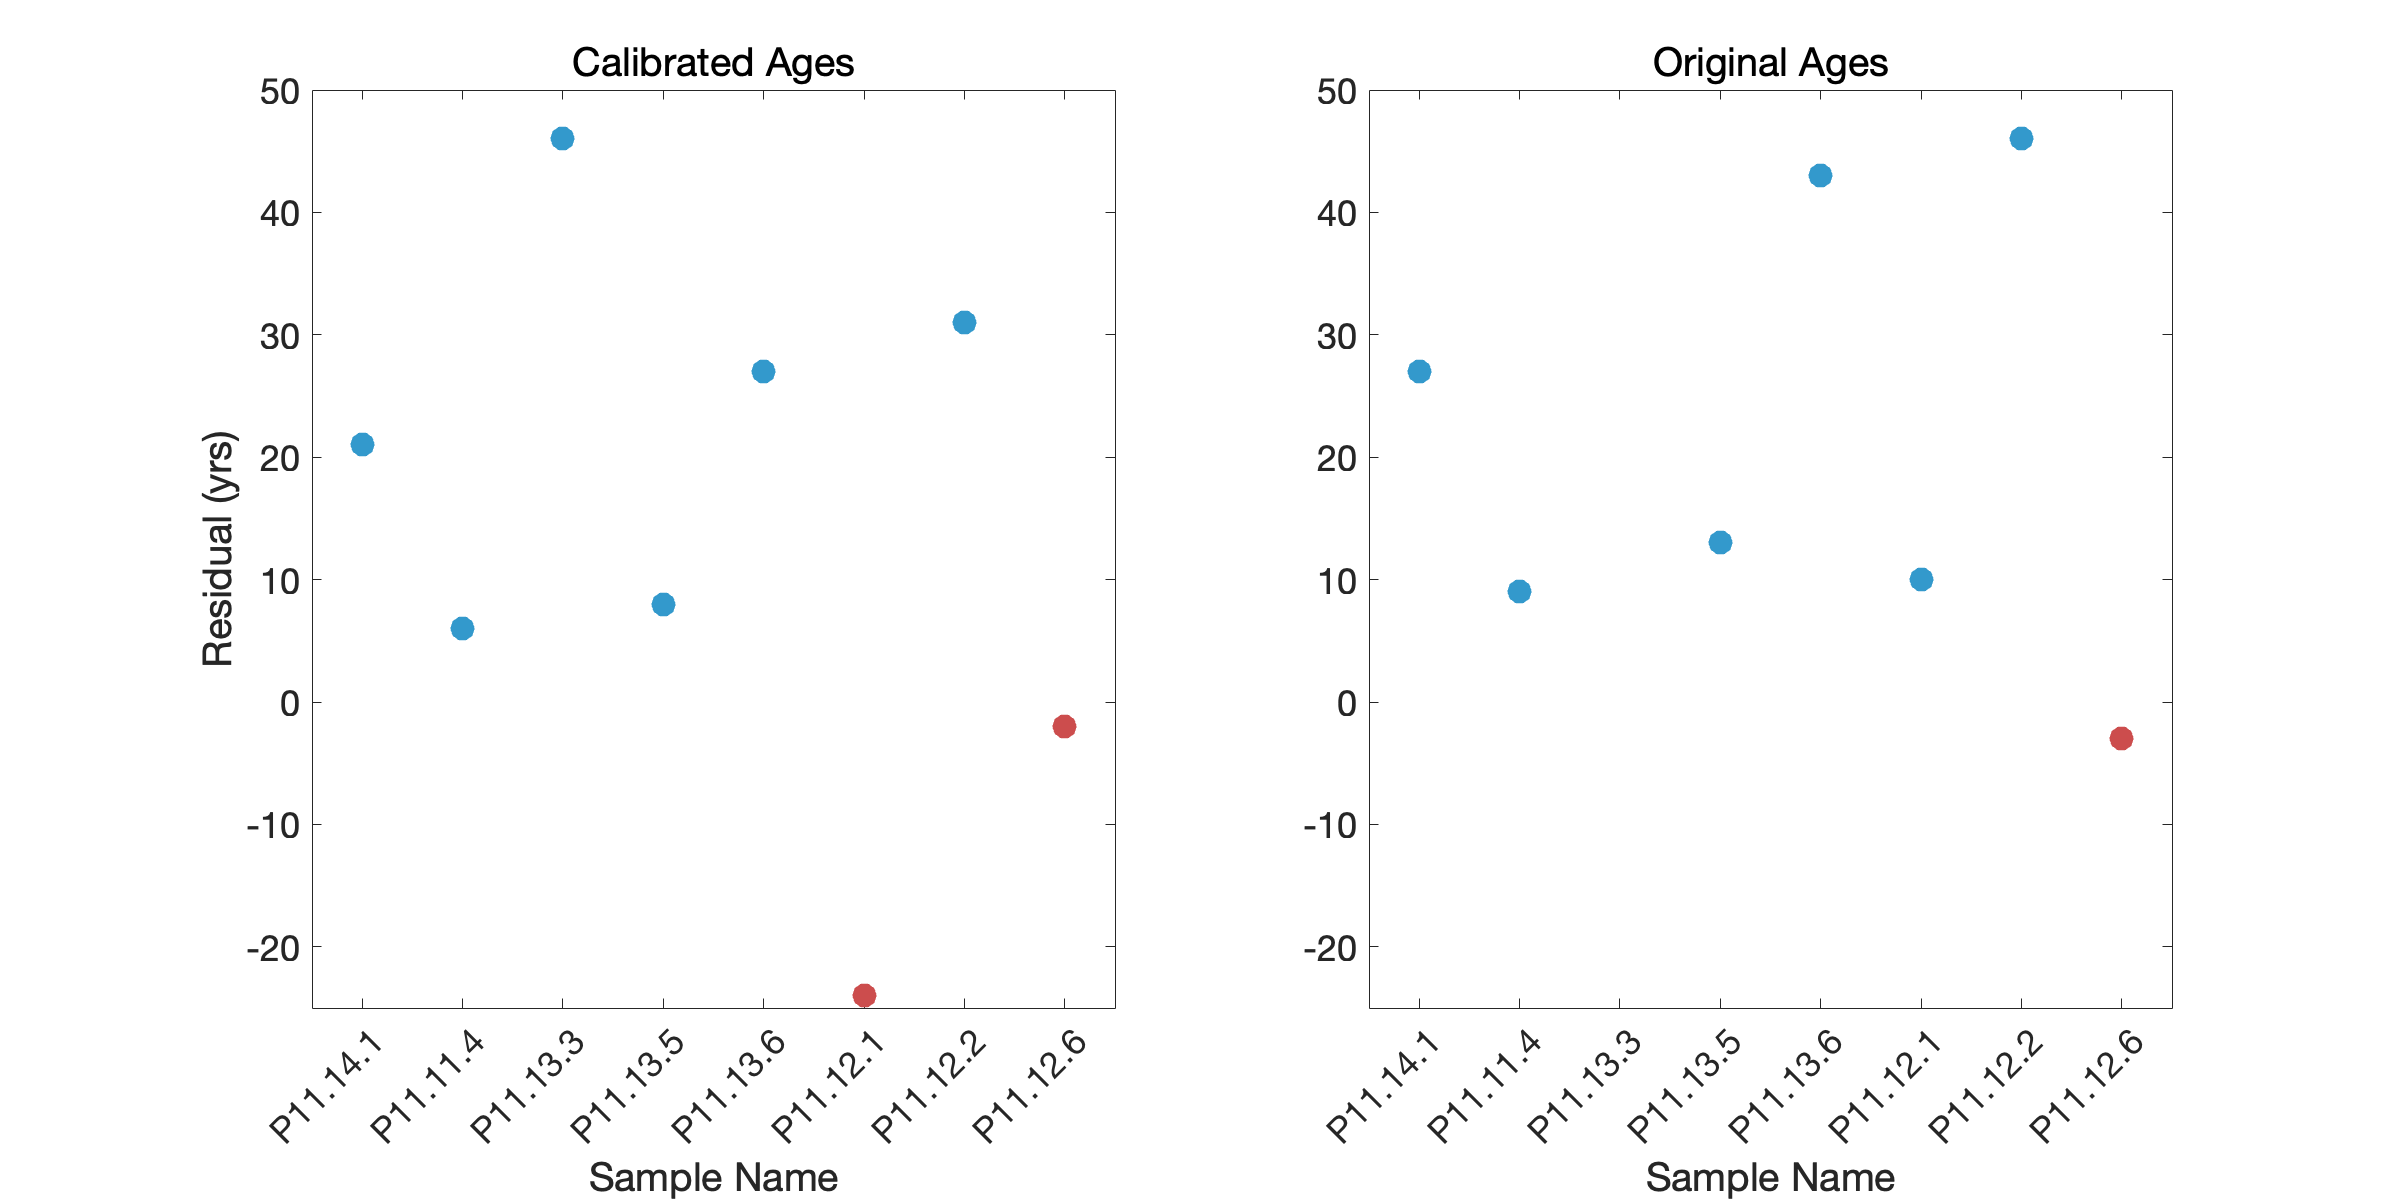

% Identify positive and negative residuals for the calibrated ages
pos_idx_fit = las.fit_resid >= 0;
neg_idx_fit = las.fit_resid < 0;

% Identify positive and negative residuals for the original ages
pos_idx_check = las.check_resid>= 0;
neg_idx_check = las.check_resid < 0;

% Convert sample names to categorical for bar alignment
cat_names = categorical(las.sample_names);
cat_names = reordercats(cat_names, las.sample_names);

% Plotting
% Set figure settings
set(0,'DefaultFigureVisible','on');
set(0,'DefaultFigureWindowStyle','normal');   % not docked

% Initialize figure
figure('Units','pixels','Position',[200 200 1200 600],'Color','w');

% Residuals for the calibrated ages
subplot(1,2,1);
hold on;

% Plot positive residuals
scatter(cat_names(pos_idx_fit), las.fit_resid(pos_idx_fit), 150, ...
    'filled', 'MarkerFaceColor', [0.2 0.6 0.8]);

% Plot negative residuals
scatter(cat_names(neg_idx_fit), las.fit_resid(neg_idx_fit), 150, ...
    'filled', 'MarkerFaceColor', [0.8 0.3 0.3]);

% Add labels and set properties
xlabel('Sample Name', 'FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
ylabel('Residual (yrs)', 'FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
title('Calibrated Ages','FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
set(gca, 'FontSize', 18, 'FontName', 'Helvetica', 'XTickLabelRotation', 45);
ylim([-25 50]);
box on;
hold off;

% Residuals for the original ages
subplot(1,2,2);
hold on;
% Plot positive residuals
scatter(cat_names(pos_idx_check), las.check_resid(pos_idx_check), 150, ...
    'filled', 'MarkerFaceColor', [0.2 0.6 0.8]);

% Plot negative residuals
scatter(cat_names(neg_idx_check), las.check_resid(neg_idx_check), 150, ...
    'filled', 'MarkerFaceColor', [0.8 0.3 0.3]);

% Add labels and set properties
xlabel('Sample Name', 'FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
title('Original Ages','FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
set(gca, 'FontSize', 18, 'FontName', 'Helvetica', 'XTickLabelRotation', 45);
ylim([-25 50]);
box on;

%sgtitle('Lassiter Coast', 'FontSize', 24, 'FontName', 'Helvetica');
hold off;
fig = gcf;
%Turn on to save a high-resolution figure
print(fig, 'las_resids.png', '-dpng', '-r600')

#### Plot residuals for Dronning Maud Land

% Identify positive and negative residuals for the calibrated ages
pos_idx_fit = dml.fit_resid >= 0;
neg_idx_fit = dml.fit_resid < 0;

% Identify positive and negative residuals for the original ages
pos_idx_check = dml.check_resid>= 0;
neg_idx_check = dml.check_resid < 0;

% Convert sample names to categorical for bar alignment
cat_names = categorical(dml.sample_names);
cat_names = reordercats(cat_names, dml.sample_names);

% Plotting
% Set figure settings
set(0,'DefaultFigureVisible','on');
set(0,'DefaultFigureWindowStyle','normal');   % not docked

% Initialize figure
figure('Units','pixels','Position',[200 200 1200 600],'Color','w');

% Residuals for the calibrated ages
subplot(1,2,1);
hold on;

% Plot positive residuals
scatter(cat_names(pos_idx_fit), dml.fit_resid(pos_idx_fit), 150, ...
    'filled', 'MarkerFaceColor', [0.2 0.6 0.8]);

% Plot negative residuals
scatter(cat_names(neg_idx_fit), dml.fit_resid(neg_idx_fit), 150, ...
    'filled', 'MarkerFaceColor', [0.8 0.3 0.3]);

% Add labels and set properties
xlabel('Sample Name', 'FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
ylabel('Residual (yrs)', 'FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
title('Calibrated Ages','FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
set(gca, 'FontSize', 18, 'FontName', 'Helvetica', 'XTickLabelRotation', 45);
ylim([-155 30]);
box on;
hold off;

% Residuals for the original ages
subplot(1,2,2);
hold on;
% Plot positive residuals
scatter(cat_names(pos_idx_check), dml.check_resid(pos_idx_check), 150, ...
    'filled', 'MarkerFaceColor', [0.2 0.6 0.8]);

% Plot negative residuals
scatter(cat_names(neg_idx_check), dml.check_resid(neg_idx_check), 150, ...
    'filled', 'MarkerFaceColor', [0.8 0.3 0.3]);

% Add labels and set properties
xlabel('Sample Name', 'FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
title('Original Ages','FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
set(gca, 'FontSize', 18, 'FontName', 'Helvetica', 'XTickLabelRotation', 45);
ylim([-700 50]);
box on;

%sgtitle('Dronning Maud Land', 'FontSize', 24, 'FontName', 'Helvetica');
hold off;
fig = gcf;
%Turn on to save a high-resolution figure
print(fig, 'dml_resids.png', '-dpng', '-r600');

#### Plot residuals for The Northern Transantarctic Mountains

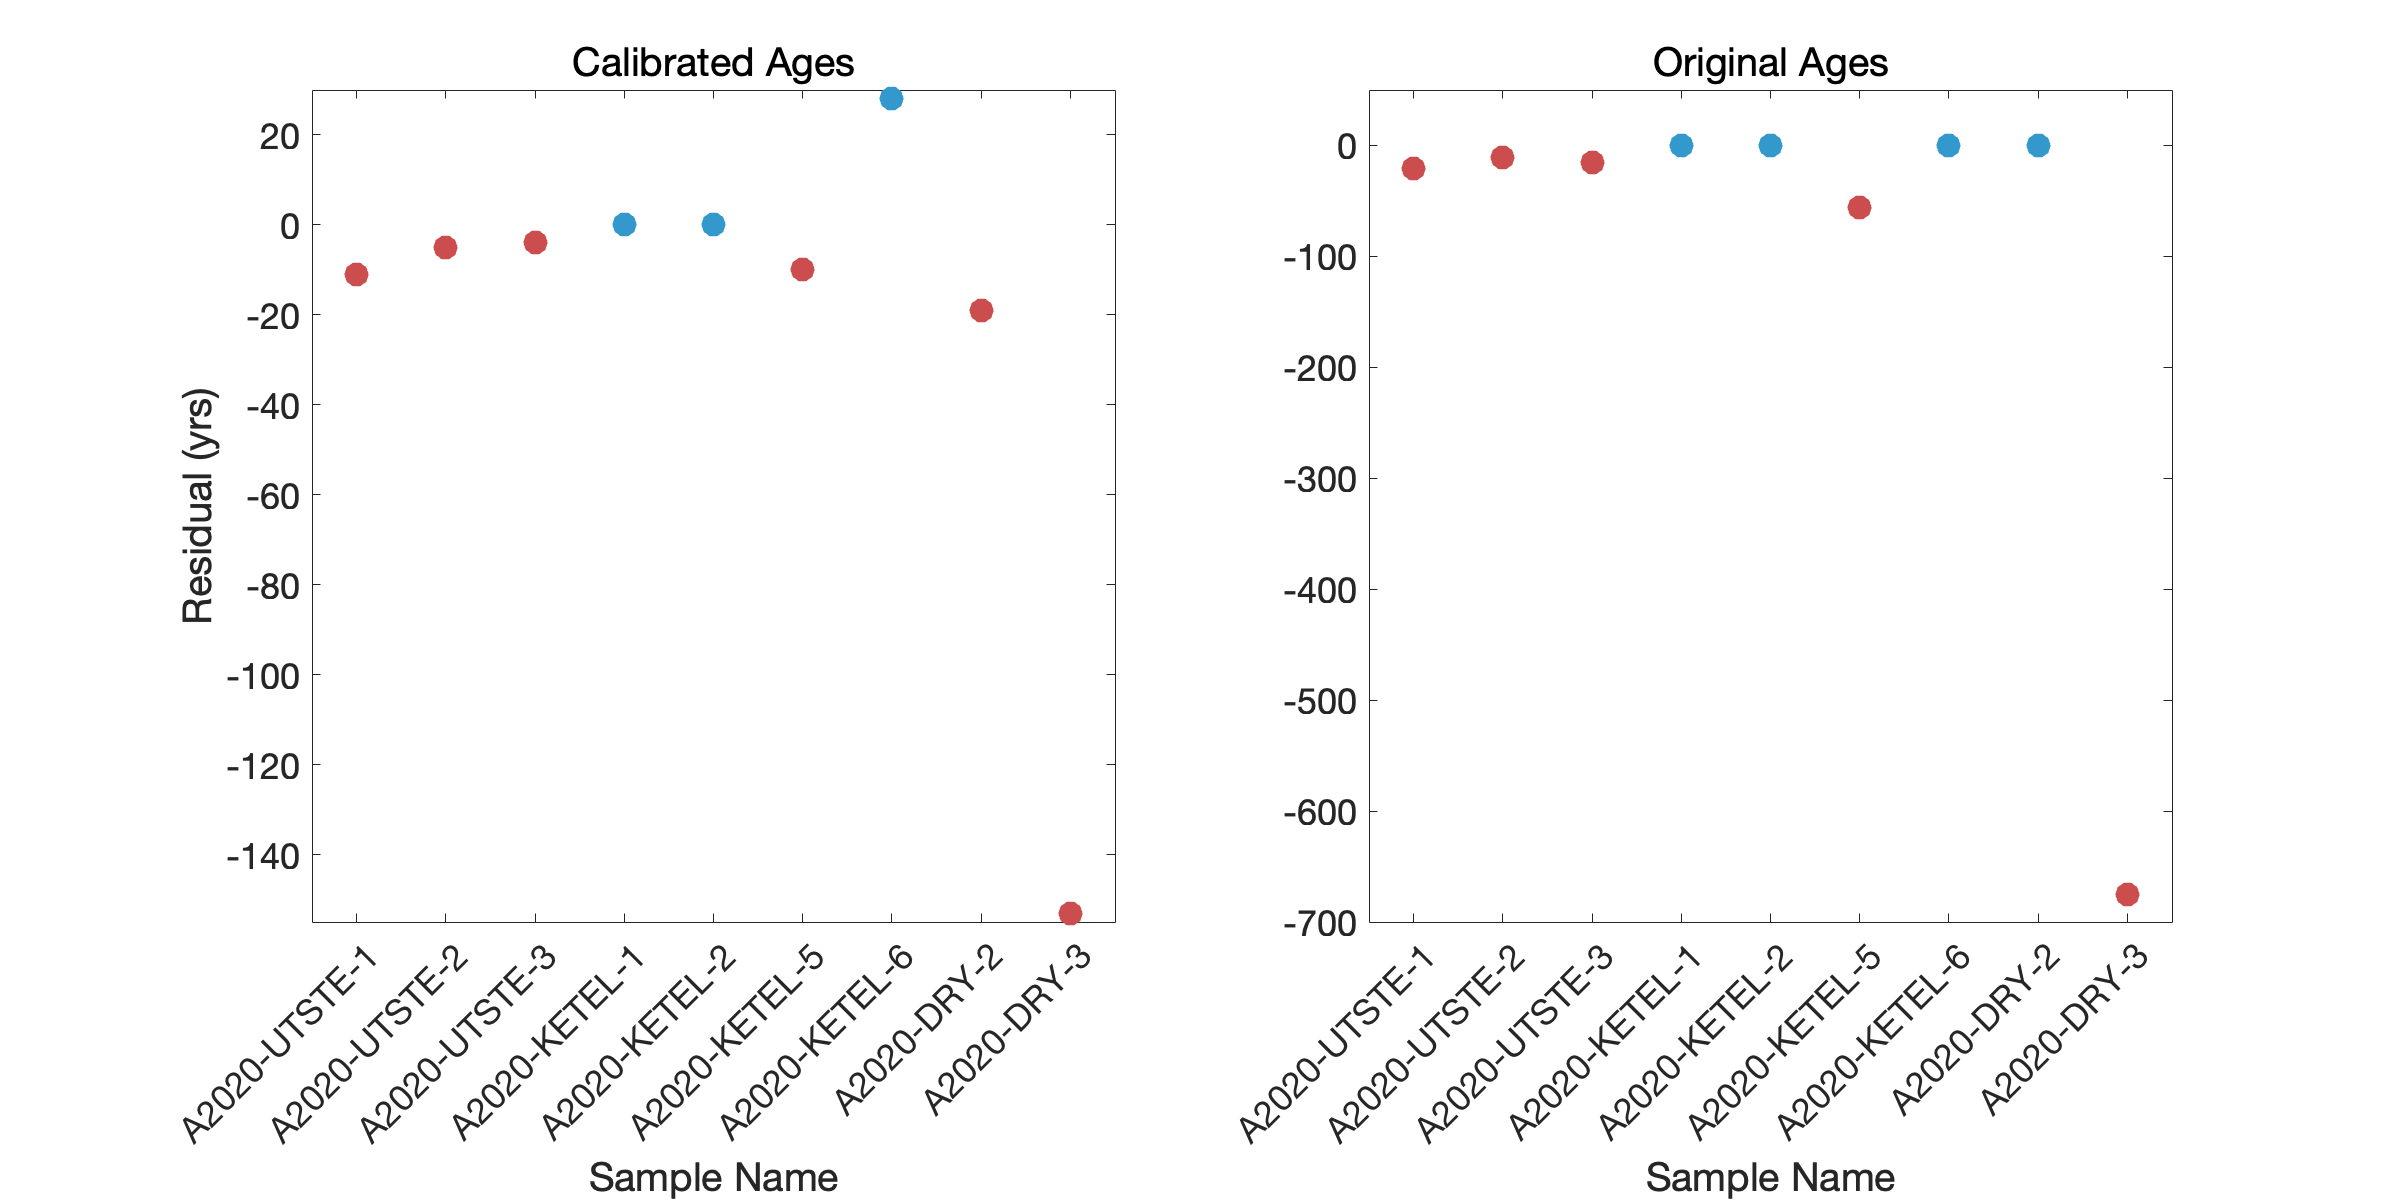

% Identify positive and negative residuals for the calibrated ages

pos_idx_fit = tam.fit_resid >= 0;
neg_idx_fit = tam.fit_resid < 0;

% Identify positive and negative residuals for the original ages
pos_idx_check = tam.check_resid>= 0;
neg_idx_check = tam.check_resid < 0;

% Convert sample names to categorical for bar alignment
cat_names = categorical(cellstr(tam.sample_names));
cat_names = reordercats(cat_names, cellstr(tam.sample_names));

% Plotting
% Set figure settings
set(0,'DefaultFigureVisible','on');
set(0,'DefaultFigureWindowStyle','normal');   % not docked

% Initialize figure
figure('Units','pixels','Position',[200 200 1600 600],'Color','w');

% Residuals for the calibrated ages
subplot(1,2,1);
hold on;

% Plot positive residuals
scatter(cat_names(pos_idx_fit), tam.fit_resid(pos_idx_fit), 150, ...
    'filled', 'MarkerFaceColor', [0.2 0.6 0.8]);

% Plot negative residuals
scatter(cat_names(neg_idx_fit), tam.fit_resid(neg_idx_fit), 150, ...
    'filled', 'MarkerFaceColor', [0.8 0.3 0.3]);

% Add labels and set properties
xlabel('Sample Name', 'FontSize', 12, 'FontWeight', 'normal', 'FontName', 'Helvetica');
ylabel('Residual (yrs)', 'FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
title('Calibrated Ages','FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
set(gca, 'FontSize', 18, 'FontName', 'Helvetica', 'XTickLabelRotation', 45);
ylim([0 500]);
ax = gca;
ax.XTick = ax.XTick(1:2:end);
box on;
hold off;

% Residuals for the original ages
subplot(1,2,2);
hold on;
% Plot positive residuals
scatter(cat_names(pos_idx_check), tam.check_resid(pos_idx_check), 150, ...
    'filled', 'MarkerFaceColor', [0.2 0.6 0.8]);

% Plot negative residuals
scatter(cat_names(neg_idx_check), tam.check_resid(neg_idx_check), 150, ...
    'filled', 'MarkerFaceColor', [0.8 0.3 0.3]);

% Add labels and set properties
xlabel('Sample Name', 'FontSize', 12, 'FontWeight', 'normal', 'FontName', 'Helvetica');
title('Original Ages','FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
set(gca, 'FontSize', 18, 'FontName', 'Helvetica', 'XTickLabelRotation', 45);
ylim([0 1300]);
ax = gca;
ax.XTick = ax.XTick(2:2:end);
box on;

%sgtitle('Northern Transantarctic Mountains', 'FontSize', 24, 'FontName', 'Helvetica');
hold off;
fig = gcf;
%Turn on to save a high-resolution figure
print(fig, 'tam_resids.png', '-dpng', '-r600');

#### Plot residuals for The Northern Transantarctic Mountains

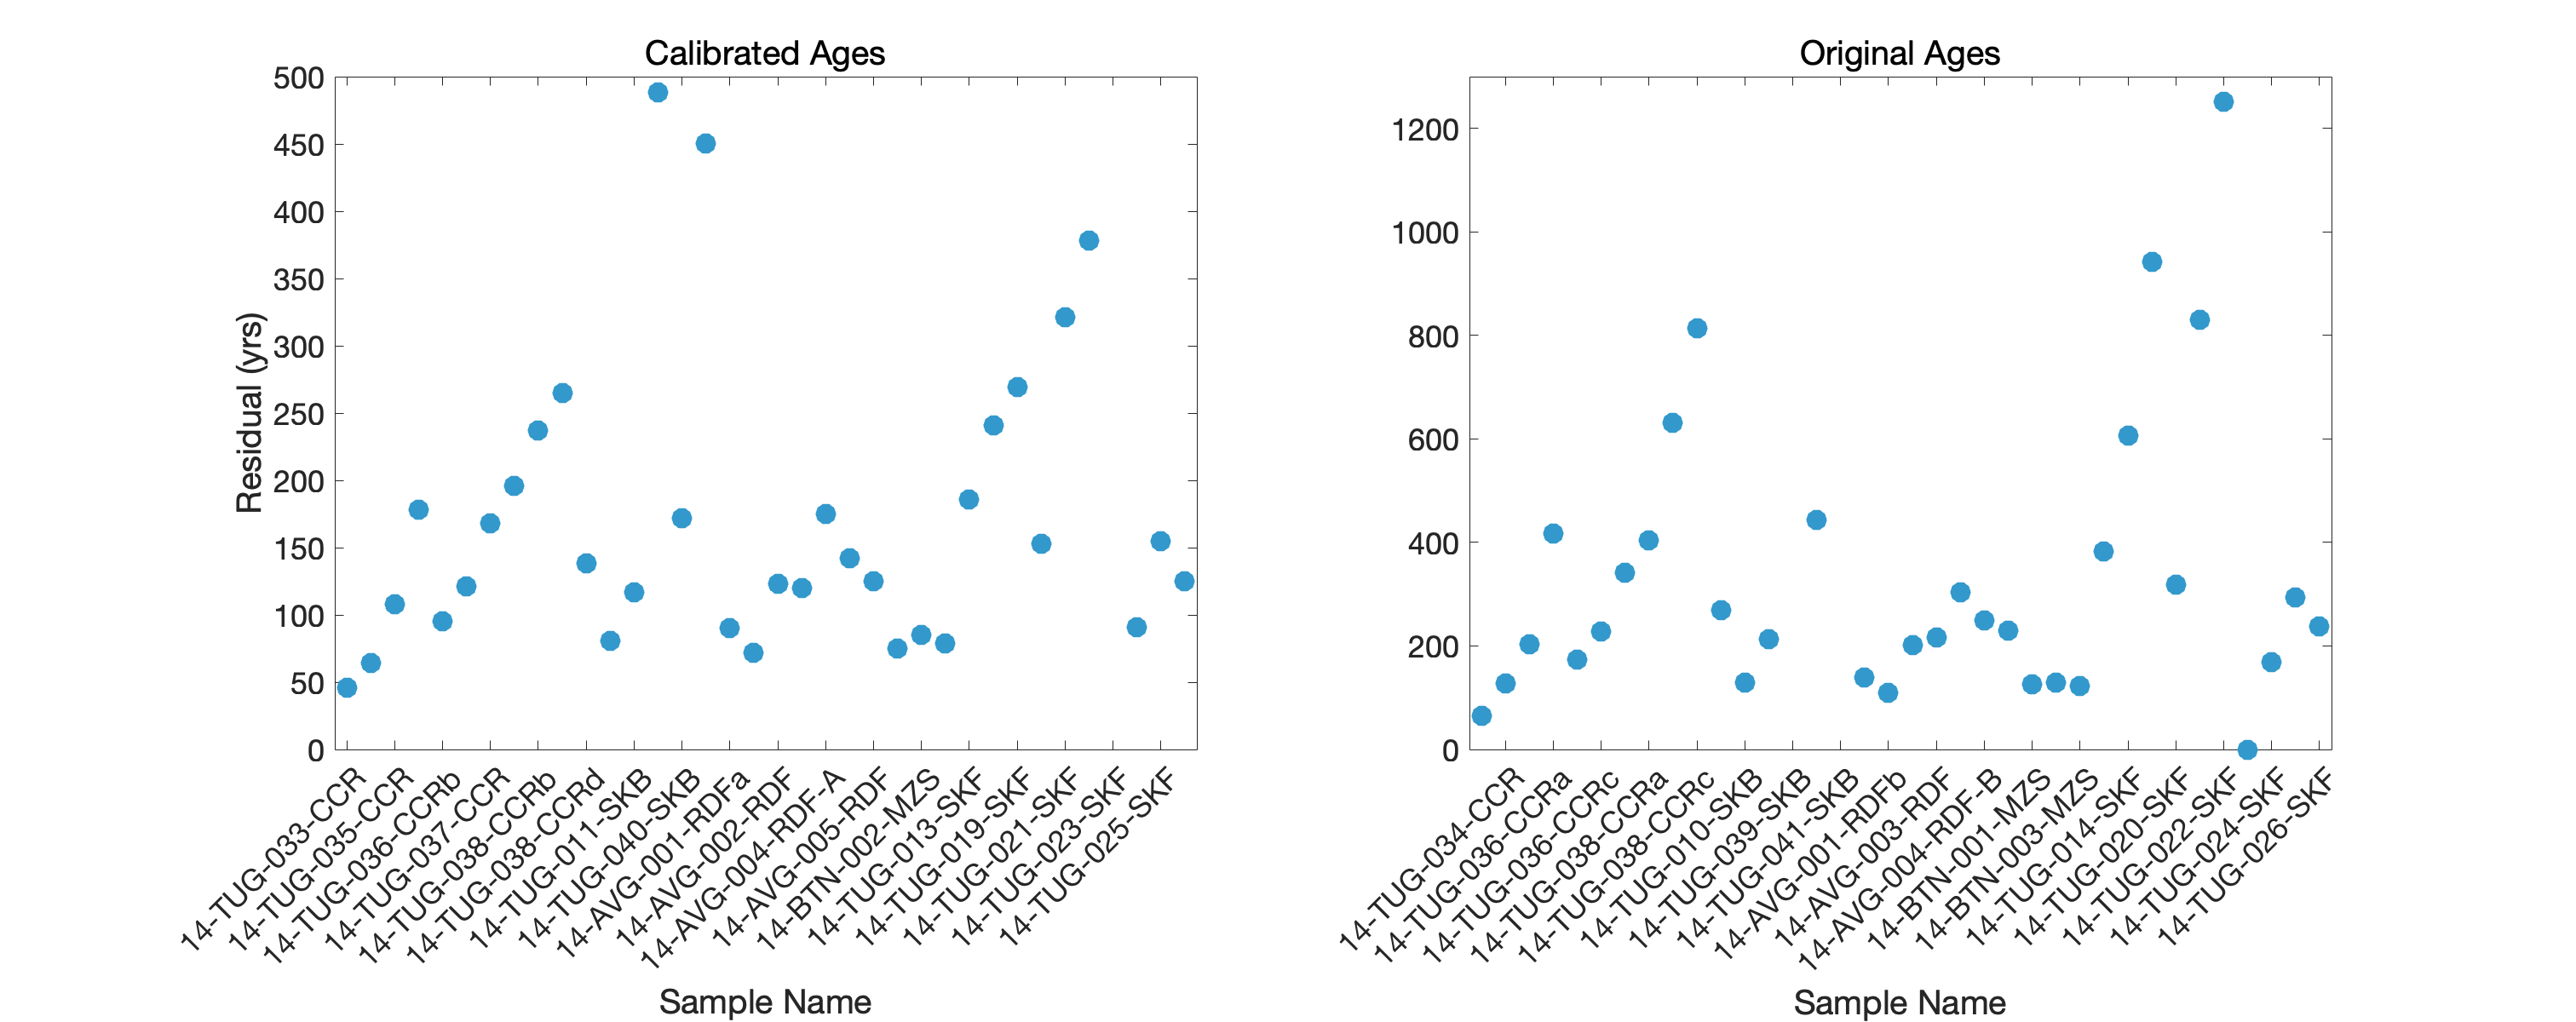

% Identify positive and negative residuals for the calibrated ages
pos_idx_fit = ase.fit_resid >= 0;
neg_idx_fit = ase.fit_resid < 0;


% Identify positive and negative residuals for the original ages
pos_idx_check = ase.check_resid>= 0;
neg_idx_check = ase.check_resid < 0;

% Convert sample names to categorical for bar alignment
cat_names = categorical(cellstr(ase.sample_names));
cat_names = reordercats(cat_names, cellstr(ase.sample_names));

% Plotting
% Set figure settings
set(0,'DefaultFigureVisible','on');
set(0,'DefaultFigureWindowStyle','normal');   % not docked

% Initialize figure
figure('Units','pixels','Position',[200 200 1600 600],'Color','w');

% Residuals for the calibrated ages
subplot(1,2,1);
hold on;

% Plot positive residuals
scatter(cat_names(pos_idx_fit), ase.fit_resid(pos_idx_fit), 150, ...
    'filled', 'MarkerFaceColor', [0.2 0.6 0.8]);

% Plot negative residuals
scatter(cat_names(neg_idx_fit), ase.fit_resid(neg_idx_fit), 150, ...
    'filled', 'MarkerFaceColor', [0.8 0.3 0.3]);

% Add labels and set properties
xlabel('Sample Name', 'FontSize', 12, 'FontWeight', 'normal', 'FontName', 'Helvetica');
ylabel('Residual (yrs)', 'FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
title('Calibrated Ages','FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
set(gca, 'FontSize', 18, 'FontName', 'Helvetica', 'XTickLabelRotation', 45);
ylim([0 400]);
ax = gca;
ax.XTick = ax.XTick(1:2:end);
box on;
hold off;


% Residuals for the original ages
subplot(1,2,2);
hold on;
% Plot positive residuals
scatter(cat_names(pos_idx_check), ase.check_resid(pos_idx_check), 150, ...
    'filled', 'MarkerFaceColor', [0.2 0.6 0.8]);

% Plot negative residuals
scatter(cat_names(neg_idx_check), ase.check_resid(neg_idx_check), 150, ...
    'filled', 'MarkerFaceColor', [0.8 0.3 0.3]);

% Add labels and set properties
xlabel('Sample Name', 'FontSize', 12, 'FontWeight', 'normal', 'FontName', 'Helvetica');
title('Original Ages','FontSize', 24, 'FontWeight', 'normal', 'FontName', 'Helvetica');
set(gca, 'FontSize', 18, 'FontName', 'Helvetica', 'XTickLabelRotation', 45);
ylim([0 400]);
ax = gca;
ax.XTick = ax.XTick(2:2:end);
box on;

%sgtitle('Pope Glacier (Amundsen Sea)', 'FontSize', 24, 'FontName', 'Helvetica');
hold off;
fig = gcf;
%Turn on to save a high-resolution figure
print(fig, 'ase_resids.png', '-dpng', '-r600');

clear pos_idx_check pos_idx_fit neg_idx_check neg_idx_fit cat_names fig

Good until here

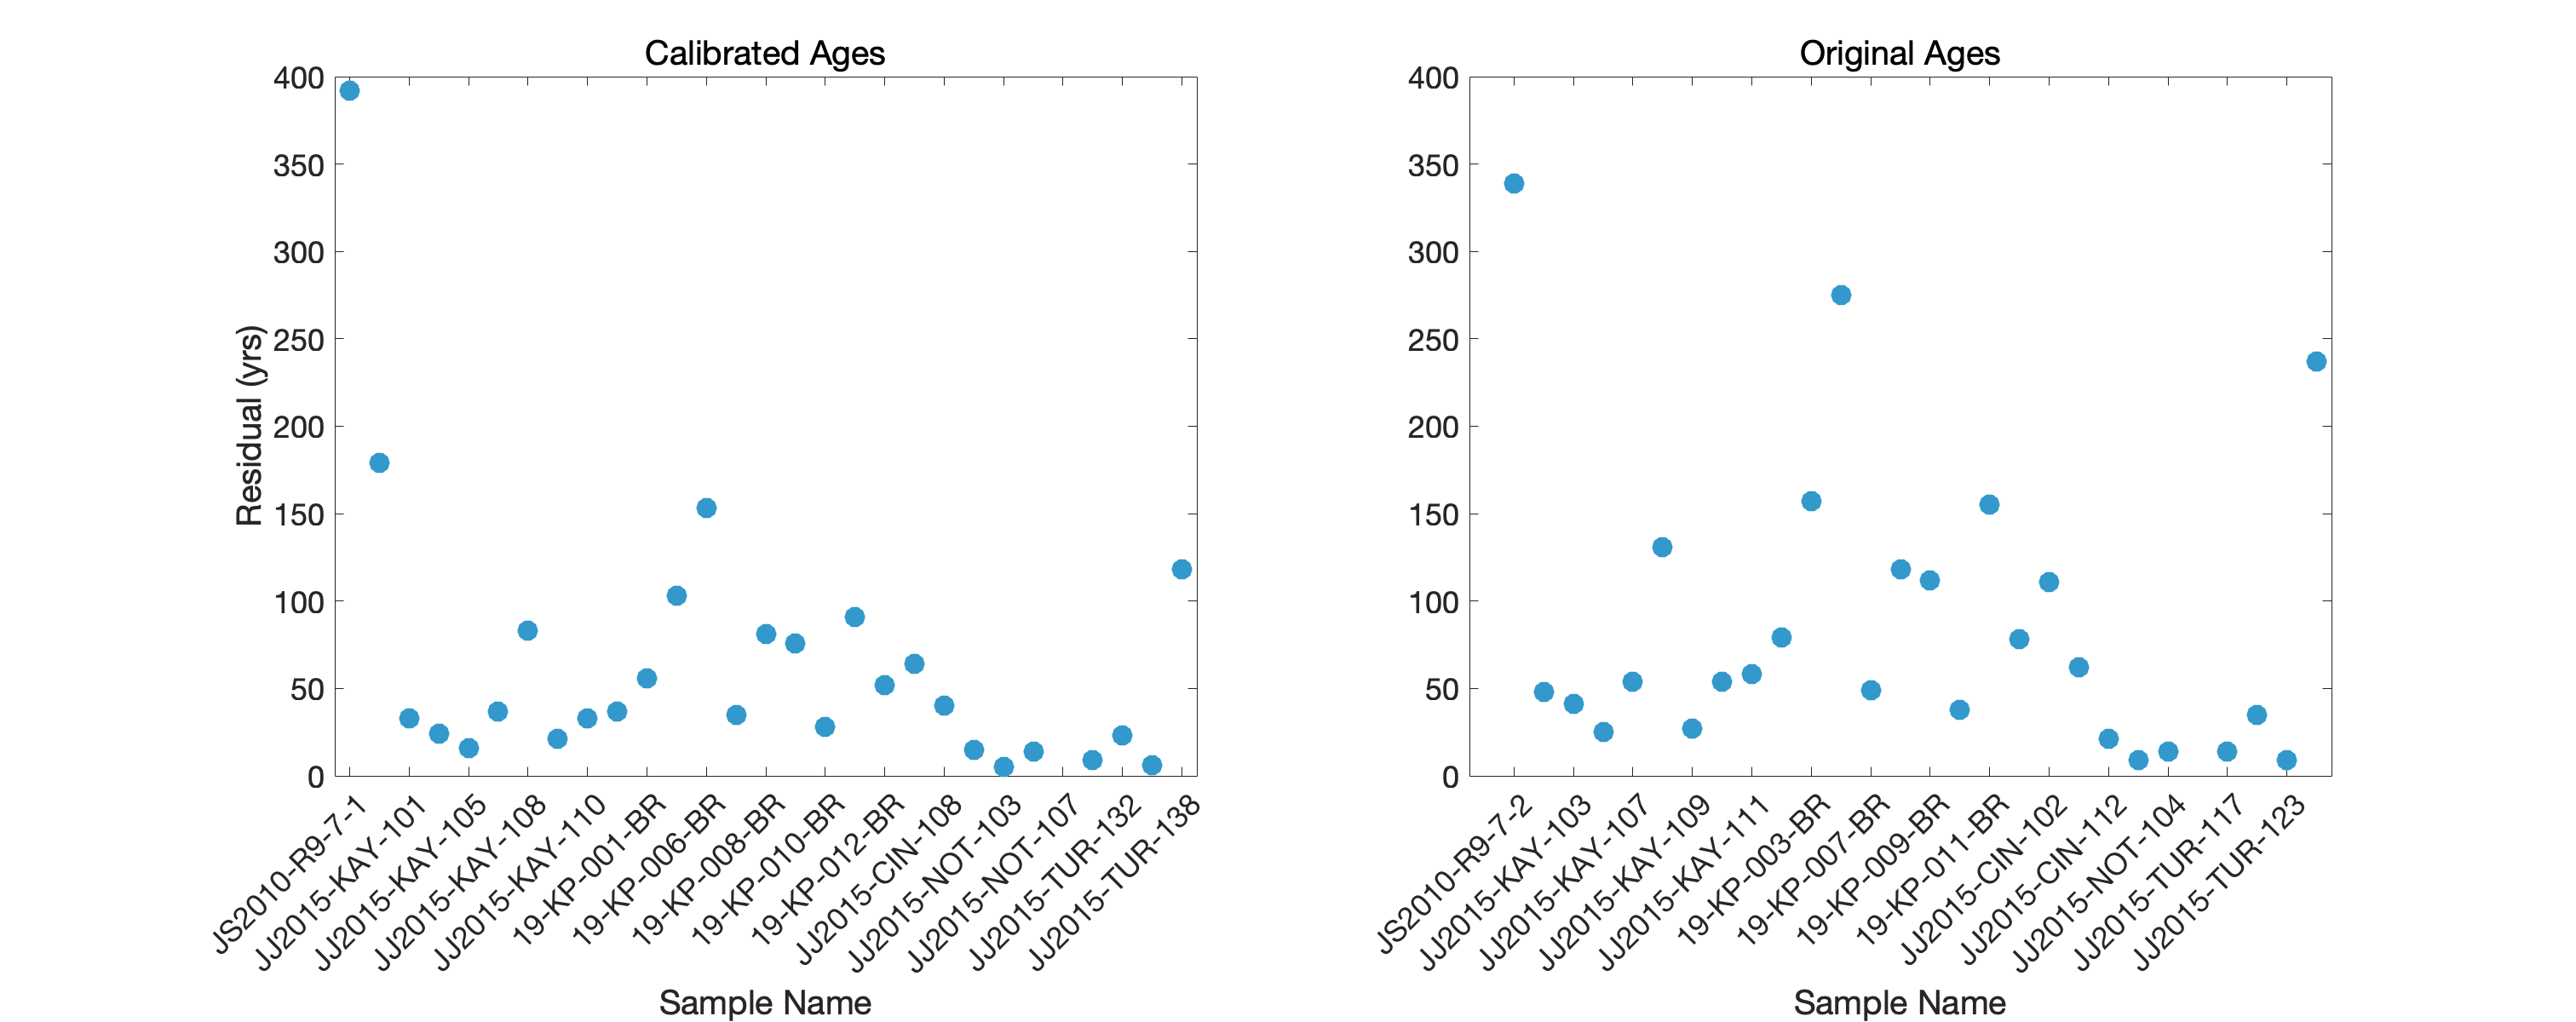

figure;

hold on;

% Original ages with uncertainty
errorbar(dml.orig_age, dml.elev, dml.orig_unc, dml.orig_unc, 'o', ...
    'horizontal', 'LineStyle', 'none', ...
    'MarkerFaceColor', [0.2 0.2 0.8], 'MarkerEdgeColor', 'k', ...
    'DisplayName', 'Original Age');

% New ages with uncertainty
errorbar(dml.calib_age, dml.elev, dml.calib_unc, dml.calib_unc, 's', ...
    'horizontal', 'LineStyle', 'none', ...
    'MarkerFaceColor', [0.8 0.2 0.2], 'MarkerEdgeColor', 'k', ...
    'DisplayName', 'New Age');

% Axis and labels
xlabel('Exposure Age (years)');
ylabel('Elevation (m)');
title('Queen Maud Land (Blue Ice Moraines)');

% Formatting
grid on;
%legend('Location', 'best');
xlim([min([dml.orig_age; dml.calib_age]) - 500, 25000]);
ylim([min(dml.elev)-25, max(dml.elev)+25]);
set(gca, 'FontSize', 16, 'FontName', 'Helvetica', 'Box', 'on');
hold off

This section plots the age difference between the data from the original publication and the data from the calibration to demonstrate the magnitude of change that occurs for samples of different ages 

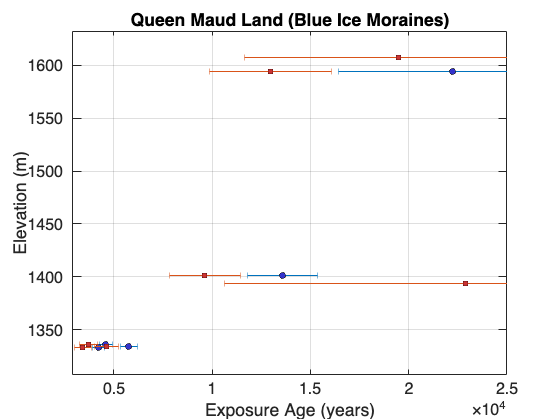

figure;
hold on
scatter(ase.orig_age, ase.age_off, 'filled');
scatter(las.orig_age, las.age_off, 'filled');

scatter(dml.orig_age, dml.age_off, 'filled');
scatter(tam.orig_age, tam.age_off, 'filled');

% Optionally format tick labels as integers
xtickformat('%.0f'); % Full numbers for x-axis
ytickformat('%.0f'); % Full numbers for y-axis

xlabel('Ages (years)');
ylabel('Age Difference');
title('Calculated Age Difference');

xlabel('Published Ages (years)');
ylabel('Age Difference (years)');
title('Calculated Age Difference for "Goehring 2019"');
figure;
scatter(ages_1138_trim, orig_age_diff, 75, 'filled');

Unrecognized function or variable 'orig_age'.


xlabel('Published Ages (years)');
ylabel('Age Difference (years)');

## Additional Figures

These additional plots are mainly to evaluate for other possible relationships in the data and were not included in the final manuscript. Or they served to generate a plot for a poster or conference talk in support of the project. For that reason they are included here as additional code but they are not necessarily commented well and they may contain bugs which prevent them from running, however they may also be useful for evaluating additional relationships in the future which is why they remain included in this code.

% Load ages as predicted by the CRONUScalc
tam.marrero_age = [4210, 5490, 8150, 11180, 8090, 9110, 10050, 10750, 12130, 12820, 9340, 6610, 7960, 16310, 11960, 16160, 6400, 5610, 6860, 7710, 8780, 8610, 7640, 6870, 6310, 6610, 10620, 11760, 13310, 10180, 11920, 13110, 23510, 7470, 9150, 8210]';
tam.marrero_unc = [430, 520, 900, 1470, 180, 320, 1150, 1410, 430, 460, 250, 160, 220, 810, 430, 830, 600, 110, 660, 720, 1000, 910, 720, 160, 150, 190, 340, 380, 590, 300, 570, 630, 2070, 180, 230, 200]';


ages = [tam.marrero_age, tam.calib_age, tam.fit_age, tam.orig_age];

figure; hold on

offsets = [-0.3, -0.1, 0.1, 0.3];   % horizontal spacing for the 4 methods
colors = {[1 0 0], [0 1 0], [0 0 1], [0 0 0]};

for i = 1:36
    for m = 1:4
        plot(i + offsets(m), ages(i,m), 'o', ...
            'MarkerEdgeColor', 'k', ...
            'MarkerFaceColor', colors{m}, ...
            'MarkerSize', 8);
    end
end

xlim([0 37])
xlabel('Sample number')
ylabel('Age')
set(gca, 'FontSize', 24, 'LineWidth', 2)

for x = 1.5:1:35.5
    xline(x, ':', ...
        'Color', [0.7 0.7 0.7], ...
        'LineWidth', 2);
end
ax = gca;
ax.YTick = [0, 5000, 10000, 15000, 20000, 25000, 30000];
ax.YAxis.Exponent = 0;
ylim([0 30000]);
legend(["CRONUScalc (PR = 12.8)", "expage (PR = 13.31)", "OEC (calibated)", "OEC (not calibrated"], 'Location', 'best')

### Plot Calibrated Ages by Latitude

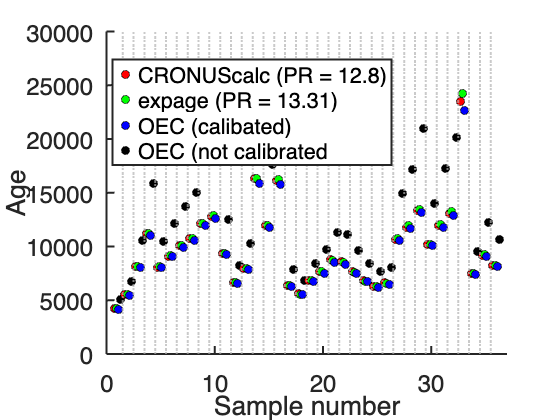

figure;
hold on;
scatter(las.calib_age, las.lat, 'red', 'filled', DisplayName='Lassiter Coast');
scatter(dml.calib_age, dml.lat, 'green', 'filled', DisplayName='Queen Maud Land');
scatter(ase.calib_age, ase.lat, 'blue', 'filled', DisplayName='Amundsen Sea Embayment');

scatter(tam.calib_age, tam.lat, 'cyan', 'filled', DisplayName='Trans-Antarctic Mountains');
xlim([0 25000])
ylabel('Latitude (degrees)')
xlabel('Exposure Age')
legend;

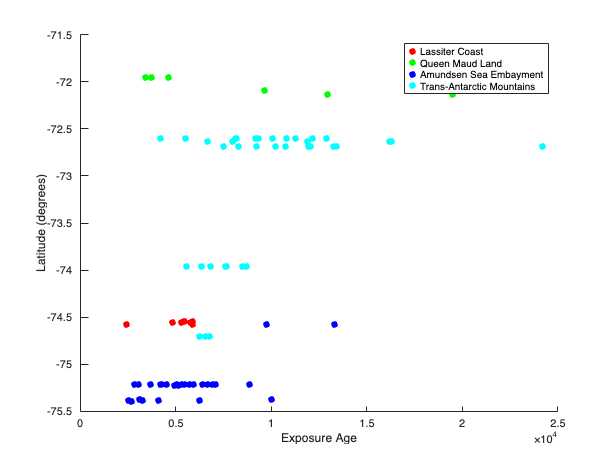


% Perform random draws of the data to determine the best fit range for the
% kay peak data

% Subset
kp_bin = [3 19 17 4 22 14];

x1 = ase.orig_age(kp_bin);
y  = ase.elev(kp_bin);
x2 = ase.calib_age(kp_bin);
x1_err = ase.orig_unc(kp_bin);
x2_err = ase.calib_unc(kp_bin);


% Monte Carlo linear fit for Kay Peak subset 
N = 5000;

s1 = zeros(N,1); i1 = zeros(N,1);
s2 = zeros(N,1); i2 = zeros(N,1);

for n = 1:N
    x1n = x1 + randn(size(x1)).*x1_err;
    x2n = x2 + randn(size(x2)).*x2_err;

    p1 = polyfit(x1n, y, 1);
    p2 = polyfit(x2n, y, 1);

    s1(n) = p1(1);  i1(n) = p1(2);
    s2(n) = p2(1);  i2(n) = p2(2);
end

% Evaluate fits on a common grid
xgrid = linspace(min([x1; x2])-100, 9000, 200);
Y1 = s1.*xgrid + i1;
Y2 = s2.*xgrid + i2;

% Mean + 95 % envelope
m1 = mean(Y1,1);
lo1 = prctile(Y1,2.5,1); hi1 = prctile(Y1,97.5,1);

m2 = mean(Y2,1);
lo2 = prctile(Y2,2.5,1); hi2 = prctile(Y2,97.5,1);

figure;
hold on;

fill([4000 7000 7000 4000], [100 100 1000 1000], [1 0.4 0.2], ...
     'EdgeColor', 'none', 'FaceAlpha', 0.1);  % HTM

fill([13700 14200 14200 13700], [100 100 1000 1000], [1 0.4 0.2], ...
     'EdgeColor', 'none', 'FaceAlpha', 0.1);  % MWP1-A

% Original ages with uncertainty
errorbar(ase.orig_age, ase.elev, ase.orig_unc, ase.orig_unc, 'horizontal', 'LineStyle', ...
    'none', 'Color', [0.3 0.3 0.3 0.4], ...
    'CapSize', 5);

% Markers
asorig = scatter(ase.orig_age, ase.elev, 80, 'o', ...
    'MarkerEdgeColor', 'none', ...
    'MarkerFaceColor', [0.3 0.3 0.3], ...
    'MarkerFaceAlpha', 0.5, ...
    'MarkerEdgeAlpha', 0.5, ...
    'DisplayName', 'Original Ages');


colors = [0.2 0.2 0.8;
          0.2 0.6 0.2;
          0.8 0.2 0.2;
          0.6 0.2 0.6];

% Loop over 4 sites
for i = 1:4
    site_idx = (ase.loc == i);

    % Error bars
    errorbar(ase.calib_age(site_idx), ase.elev(site_idx), ...
        ase.calib_unc(site_idx), ase.calib_unc(site_idx), ...
        'horizontal', 'LineStyle', 'none', ...
        'Color', [colors(i,:) 0.4], 'CapSize', 10);

    % Scatter points
    newdat(i) = scatter(ase.calib_age(site_idx), ase.elev(site_idx), 120, 's', ...
        'MarkerEdgeColor', 'none', ...
        'MarkerFaceColor', colors(i,:), ...
        'MarkerFaceAlpha', 1, ...
        'DisplayName', sprintf('Site %d', i));
end

% Add Kay Peak best-fit lines + 95 % bands to current axes
hold on

% Calibrated
fill([xgrid fliplr(xgrid)], [lo2 fliplr(hi2)], [0.2 0.6 0.2], ...
     'FaceAlpha',0.18, 'EdgeColor','none', 'HandleVisibility','off');
h2 = plot(xgrid, m2, '-', 'Color',[0.2 0.6 0.2], ...
          'LineWidth',2, 'DisplayName','Kay Peak (calib fit)');

% Compute slope stats
slope_mean = mean(s2);
slope_lo = prctile(s2, 2.5);
slope_hi = prctile(s2, 97.5);

% Add text
text(9100, 450, sprintf('Slope: %.4f ± %.4f', slope_mean, (slope_hi - slope_lo)/2), ...
     'FontSize', 20, 'FontName', 'Helvetica', 'Color', [0.2 0.6 0.2]);

% Original
fill([xgrid fliplr(xgrid)], [lo1 fliplr(hi1)], [0.15 0.15 0.15], ...
     'FaceAlpha',0.15, 'EdgeColor','none', 'HandleVisibility','off');
h1 = plot(xgrid, m1, '-', 'Color',[0.15 0.15 0.15], ...
          'LineWidth',2, 'DisplayName','Kay Peak (orig fit)');

% Compute slope stats
slope_mean2 = mean(s1);
slope_lo2 = prctile(s1, 2.5);
slope_hi2 = prctile(s1, 97.5);

% Add text
text(9100, 400, sprintf('Slope: %.4f ± %.4f', slope_mean2, (slope_hi2 - slope_lo2)/2), ...
     'FontSize', 20, 'FontName', 'Helvetica', 'Color', [0.15 0.15 0.15]);
text(3500, 700, 'Holocene Themal Maximum', 'FontSize', 20, 'FontName', 'Helvetica');
text(12500, 700, 'Meltwater Pulse 1A', 'FontSize', 20, 'FontName', 'Helvetica');


% Keep on top
uistack([h1 h2],'bottom');


% Axis and labels
xlabel('Exposure Age (years)');
ylabel('Elevation (m)');
%title('Pope Glacier and Bear Penninsula');


% Formatting and Settings
grid on;
%legend('Location', 'best');
xlim([min([ase.orig_age; ase.calib_age]) - 500, max([ase.orig_age; ase.calib_age]) + 700]);
ylim([min(ase.elev)-25, max(ase.elev)+25]);
set(gca, 'FontSize', 20, 'FontName', 'Helvetica', 'Box', 'on', 'YGrid', 'off');
ax = gca;
ax.XAxis.Exponent = 0;
hold off
legend([asorig newdat(1) newdat(2) newdat(3) newdat(4)], {'Original Data', 'Bear Penninsula', 'Kay Peak', 'Notebook Cliffs', 'Turtle Rock'});
set(gcf,'Position',[100 100 1500 1000]);
fig = gcf;
%Turn on to save a high-resolution figure
%print(fig, 'aseslopecompare.png', '-dpng', '-r600')

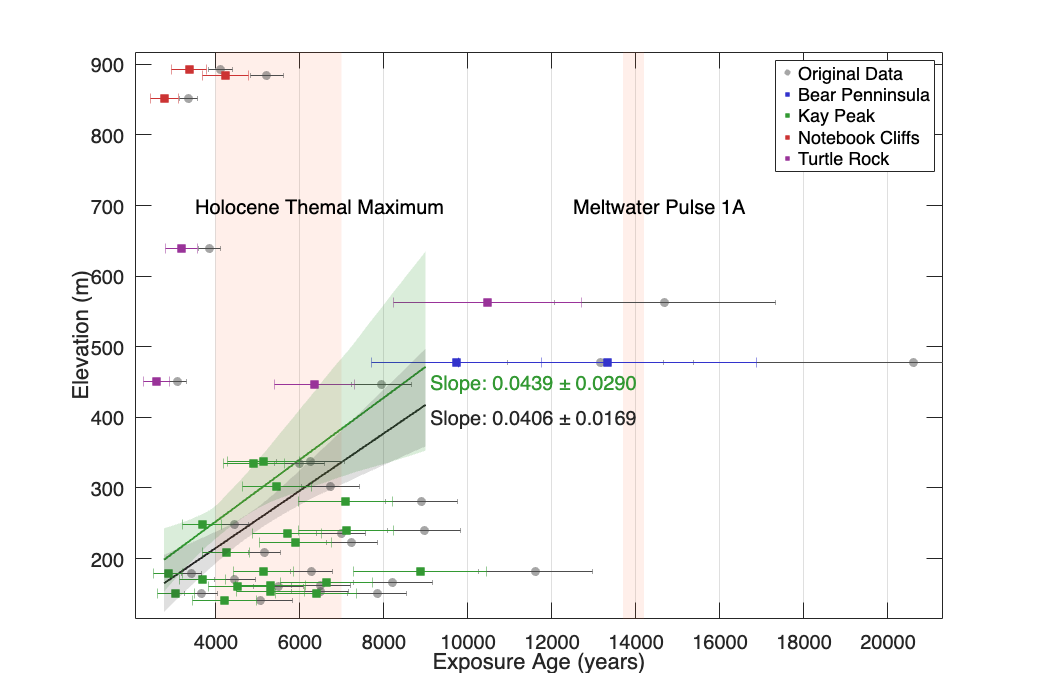

% Set up figure properties
set(0,'DefaultFigureVisible','on');
set(0,'DefaultFigureWindowStyle','normal');

figure('Color','w'); hold on;

% Shaded intervals
fill([4000 7000 7000 4000], [100 100 1000 1000], [1 0.4 0.2], ...
     'EdgeColor','none','FaceAlpha',0.10);  % HTM
fill([13700 14200 14200 13700], [100 100 1000 1000], [1 0.4 0.2], ...
     'EdgeColor','none','FaceAlpha',0.10);  % MWP1-A

%  Original ages with uncertainty 
errorbar(ase.orig_age, ase.elev, ase.orig_unc, ase.orig_unc, ...
    'horizontal','LineStyle','none','Color',[0.3 0.3 0.3 0.4],'CapSize',5);

asorig = scatter(ase.orig_age, ase.elev, 80, 'o', ...
    'MarkerEdgeColor','none','MarkerFaceColor',[0.3 0.3 0.3], ...
    'MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5, ...
    'DisplayName','Original Data');

% Define site colors
colors = [0.2 0.2 0.8;   % Bear Peninsula
          0.2 0.6 0.2;   % Kay Peak
          0.8 0.2 0.2;   % Notebook Cliffs
          0.6 0.2 0.6];  % Turtle Rock

% Calibrated points by site
for i = 1:4
    site_idx = (ase.loc == i);
        errorbar(ase.calib_age(site_idx), ase.elev(site_idx), ...
            ase.calib_unc(site_idx), ase.calib_unc(site_idx), ...
            'horizontal','LineStyle','none','Color',[colors(i,:) 0.4], 'CapSize',10);
    
        newdat(i) = scatter(ase.calib_age(site_idx), ase.elev(site_idx), 120, 's', ...
            'MarkerEdgeColor','none','MarkerFaceColor',colors(i,:), ...
            'MarkerFaceAlpha',1, 'DisplayName',sprintf('Site %d', i));
end

% Main Formatting
ylabel('Elevation (m)');
grid on;
xlim([min([ase.orig_age; ase.calib_age]) - 500, max([ase.orig_age; ase.calib_age]) + 700]);
ylim([min(ase.elev)-25, max(ase.elev)+25]);
set(gca,'FontSize',20,'FontName','Helvetica','Box','on','YGrid','off');
axMain = gca; axMain.XAxis.Exponent = 0; axMain.XGrid = 'on';
text(axMain, 3500, 700, 'Holocene Thermal Maximum', 'FontSize', 20, 'FontName', 'Helvetica');
text(axMain, 12500, 700, 'Meltwater Pulse 1A', 'FontSize', 20, 'FontName', 'Helvetica');

% Bottom Ribbon
kp     = (ase.loc == 2 & ase.elev<200 & ase.orig_age<10000);
x_orig = ase.orig_age(kp);  x_orig = x_orig(isfinite(x_orig));
x_cal  = ase.calib_age(kp); x_cal  = x_cal(isfinite(x_cal));

% Common x-grid across x-range
XL  = axMain.XLim;
xk  = linspace(XL(1), XL(2), 600);

% Bandwidths
bw1 = 0.9*min(std(x_orig), iqr(x_orig)/1.34)*numel(x_orig)^(-1/5);
bw2 = 0.9*min(std(x_cal),  iqr(x_cal)/1.34)*numel(x_cal)^(-1/5);
if ~isfinite(bw1) || bw1<=0, bw1 = []; end
if ~isfinite(bw2) || bw2<=0, bw2 = []; end

% KDEs
f1 = ksdensity(x_orig, xk, 'Bandwidth', bw1);
f2 = ksdensity(x_cal,  xk, 'Bandwidth', bw2);

% Normalize
ftot = f1 + f2;  den = max(ftot);  if den<=0 || ~isfinite(den), den = 1; end
f1n  = f1 / den;
f2n  = (f1 + f2) / den;

% Ribbon axis
posM = axMain.Position;              % [left bottom width height]
hFrac = 0.18;                        % ribbon height as fraction of main
hK   = posM(4) * hFrac;              % ribbon height
axK  = axes('Position',[posM(1) posM(2) posM(3) hK], ...
            'Color','none','Box','off','XLim',XL,'YLim',[0 1], ...
            'FontName','Helvetica','FontSize',20);
axMain.Position = [posM(1) posM(2)+hK posM(3) posM(4)-hK];

% Move ticks/label to the ribbon
axK.XTick = axMain.XTick;
axMain.XTick = [];
xlabel(axK,'Exposure Age (years)');
ylabel(axK, 'Probability');

hold(axK,'on')
fill(axK, [xk fliplr(xk)], [zeros(size(xk)) fliplr(f1n)], ...
     [0.40 0.40 0.40], 'EdgeColor','none', 'FaceAlpha',0.28, 'HandleVisibility','off');
fill(axK, [xk fliplr(xk)], [f1n fliplr(f2n)], ...
     [0.20 0.60 0.20], 'EdgeColor','none', 'FaceAlpha',0.28, 'HandleVisibility','off');
xline(axK, mean(x_orig), 'Color', [0.45 0.45 0.45 1], 'LineWidth', 2);
xline(axK, mean(x_cal), 'Color', [0.20 0.60 0.20 1], 'LineWidth', 2);
text(axK, 6400, 0.9, sprintf('Mean Age: %0.0f', mean(x_orig)), 'FontSize', 20, 'FontName', 'Helvetica', 'Color', [0.15 0.15 0.15])
text(axK, 2100, 0.95, sprintf('Mean Age: %0.0f', mean(x_cal)), 'FontSize', 20, 'FontName', 'Helvetica', 'Color', [0.20 0.60 0.20])



% Clean ribbon axis
axK.YTick = []; axK.TickDir = 'out'; axK.Layer = 'top';
ylim(axK, [0 max(f2n)+0.05])

% Linkaxes
linkaxes([axMain axK],'x');
axes(axMain);

% Formatting and settings
set(gcf,'Position',[100 100 1500 1000]);
axK.XAxis.Exponent = 0;
axK.XTick = [4000 6000 8000 10000 12000 14000 16000 18000 20000];
grid on;
set(axMain, 'XGrid', 'on', 'YGrid', 'off')
legend([asorig newdat(1) newdat(2) newdat(3) newdat(4)], ...
       {'Original Data','Bear Penninsula','Kay Peak','Notebook Cliffs','Turtle Rock'});

fig = gcf;
%Turn on to save a high-resolution figure
%print(fig, 'aselowerkpcompare.png', '-dpng', '-r600')


% Performs the same thing as the code above but for a single site only

% General figure settings
set(0,'DefaultFigureVisible','on');
set(0,'DefaultFigureWindowStyle','normal');   % not docked
figure('Color','w'); hold on;

% Intervals
fill([4000 7000 7000 4000], [100 100 1000 1000], [1 0.4 0.2], ...
     'EdgeColor','none','FaceAlpha',0.30);  % HTM


% Site colors
colors = [0.2 0.2 0.8;   % Bear Peninsula
          0.2 0.6 0.2;   % Kay Peak
          0.8 0.2 0.2;   % Notebook Cliffs
          0.6 0.2 0.6];  % Turtle Rock

% Calibrated points
for i = 2
    site_idx = (ase.loc == i);

            % Original ages with uncertainty
        errorbar(ase.orig_age(site_idx), ase.elev(site_idx), ase.orig_unc(site_idx), ase.orig_unc(site_idx), ...
            'horizontal','LineStyle','none','Color',[0.3 0.3 0.3 0.4],'CapSize',5);

        asorig = scatter(ase.orig_age(site_idx), ase.elev(site_idx), 150, 'o', ...
            'MarkerEdgeColor','none','MarkerFaceColor',[0.3 0.3 0.3], ...
            'MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5, ...
            'DisplayName','Original Data');

        errorbar(ase.calib_age(site_idx), ase.elev(site_idx), ...
            ase.calib_unc(site_idx), ase.calib_unc(site_idx), ...
            'horizontal','LineStyle','none','Color',[colors(i,:) 0.4], 'CapSize',10);
    
        newdat(i) = scatter(ase.calib_age(site_idx), ase.elev(site_idx), 200, 's', ...
            'MarkerEdgeColor','none','MarkerFaceColor',colors(i,:), ...
            'MarkerFaceAlpha',1, 'DisplayName',sprintf('Site %d', i));

end

% Main plot formatting
ylabel('Elevation (m)');
grid on;
xlim([min([ase.orig_age; ase.calib_age]) - 500, 14000]);
ylim([min(ase.elev)-25, 400]);
set(gca,'FontSize',20,'FontName','Helvetica','Box','on','YGrid','off');
axMain = gca; axMain.XAxis.Exponent = 0; axMain.XGrid = 'on';
text(axMain, 3950, 375, 'Holocene Thermal Maximum', 'FontSize', 24, 'FontName', 'Helvetica');

% Bottom ribbon
kp     = (ase.loc == 2 & ase.elev<200 & ase.orig_age<10000);
x_orig = ase.orig_age(kp);  x_orig = x_orig(isfinite(x_orig));
x_cal  = ase.calib_age(kp); x_cal  = x_cal(isfinite(x_cal));

% Common x-grid across x-range
XL  = axMain.XLim;
xk  = linspace(XL(1), XL(2), 600);

% Bandwidths
bw1 = 0.9*min(std(x_orig), iqr(x_orig)/1.34)*numel(x_orig)^(-1/5);
bw2 = 0.9*min(std(x_cal),  iqr(x_cal)/1.34)*numel(x_cal)^(-1/5);
if ~isfinite(bw1) || bw1<=0, bw1 = []; end
if ~isfinite(bw2) || bw2<=0, bw2 = []; end

% KDEs
f1 = ksdensity(x_orig, xk, 'Bandwidth', bw1);
f2 = ksdensity(x_cal,  xk, 'Bandwidth', bw2);

% Normalize
ftot = f1 + f2;  den = max(ftot);  if den<=0 || ~isfinite(den), den = 1; end
f1n  = f1 / den;
f2n  = (f1 + f2) / den;

% Ribbon axis
posM = axMain.Position;              % [left bottom width height]
hFrac = 0.18;                        % ribbon height as fraction of main
hK   = posM(4) * hFrac;              % ribbon height
axK  = axes('Position',[posM(1) posM(2) posM(3) hK], ...
            'Color','none','Box','off','XLim',XL,'YLim',[0 1], ...
            'FontName','Helvetica','FontSize',20);
axMain.Position = [posM(1) posM(2)+hK posM(3) posM(4)-hK];
axK.XTick = axMain.XTick;
axMain.XTick = [];
xlabel(axK,'Exposure Age (years)');
ylabel(axK, 'Probability');

hold(axK,'on')
fill(axK, [4000 7000 7000 4000], [0 0 1.2 1.2], [1 0.4 0.2], ...
     'EdgeColor','none','FaceAlpha',0.30);  % HTM
fill(axK, [xk fliplr(xk)], [zeros(size(xk)) fliplr(f1n)], ...
     [0.40 0.40 0.40], 'EdgeColor','none', 'FaceAlpha',0.5, 'HandleVisibility','off');
fill(axK, [xk fliplr(xk)], [f1n fliplr(f2n)], ...
     [0.20 0.60 0.20], 'EdgeColor','none', 'FaceAlpha',0.5, 'HandleVisibility','off');
xline(axK, mean(x_orig), 'Color', [0.45 0.45 0.45 1], 'LineWidth', 4);
xline(axK, mean(x_cal), 'Color', [0.20 0.60 0.20 1], 'LineWidth', 4);
text(axK, 6400, 0.9, sprintf('Mean Age: %0.0f', mean(x_orig)), 'FontSize', 24, 'FontName', 'Helvetica', 'Color', [0.15 0.15 0.15])
text(axK, 2100, 0.95, sprintf('Mean Age: %0.0f', mean(x_cal)), 'FontSize', 24, 'FontName', 'Helvetica', 'Color', [0.20 0.60 0.20])


axK.YTick = []; axK.TickDir = 'out'; axK.Layer = 'top';
ylim(axK, [0 max(f2n)+0.05])

% Linkaxes
linkaxes([axMain axK],'x');
axes(axMain);  

% Formatting and settings
set(gcf,'Position',[100 100 1500 1000]);
axK.XAxis.Exponent = 0;
axK.XTick = [4000 6000 8000 10000 12000 14000];
grid on;
set(axMain, 'XGrid', 'on', 'YGrid', 'off')
set(axMain, 'FontSize', 24, 'FontName', 'Helvetica', 'Box', 'on','YGrid', 'off');
set(axK, 'FontSize', 24, 'FontName', 'Helvetica', 'Box', 'on','YGrid', 'off');
legend([asorig newdat(2)], ...
       {'Original Data', 'Kay Peak'}); %, 'Bear Penninsula', 'Notebook Cliffs','Turtle Rock'});
% Cna uncomment the site above to select a specifc site for plotting

fig = gcf;
%Turn on to save a high-resolution figure
%print(fig, 'aselowerkpcompare.png', '-dpng', '-r600')


### Idealized Thinning Profile

This section creates a simplified demonstration showing how thinning may occur down an elevation profile of three data points.

figure;
demo_data_x = [15, 12, 9];
demo_data_y = [500, 350, 200];


scatter(demo_data_x, demo_data_y, 200, 'filled', 'o');
xlabel('Exposure Age (ka)')
ylabel('Elevation (m.a.s.l.)')
set(gca, 'FontSize', 28, 'FontName', 'Helvetica', "LineWidth", 1.5);
ylim([150 550]);
clear demo_data_x demo_data_y



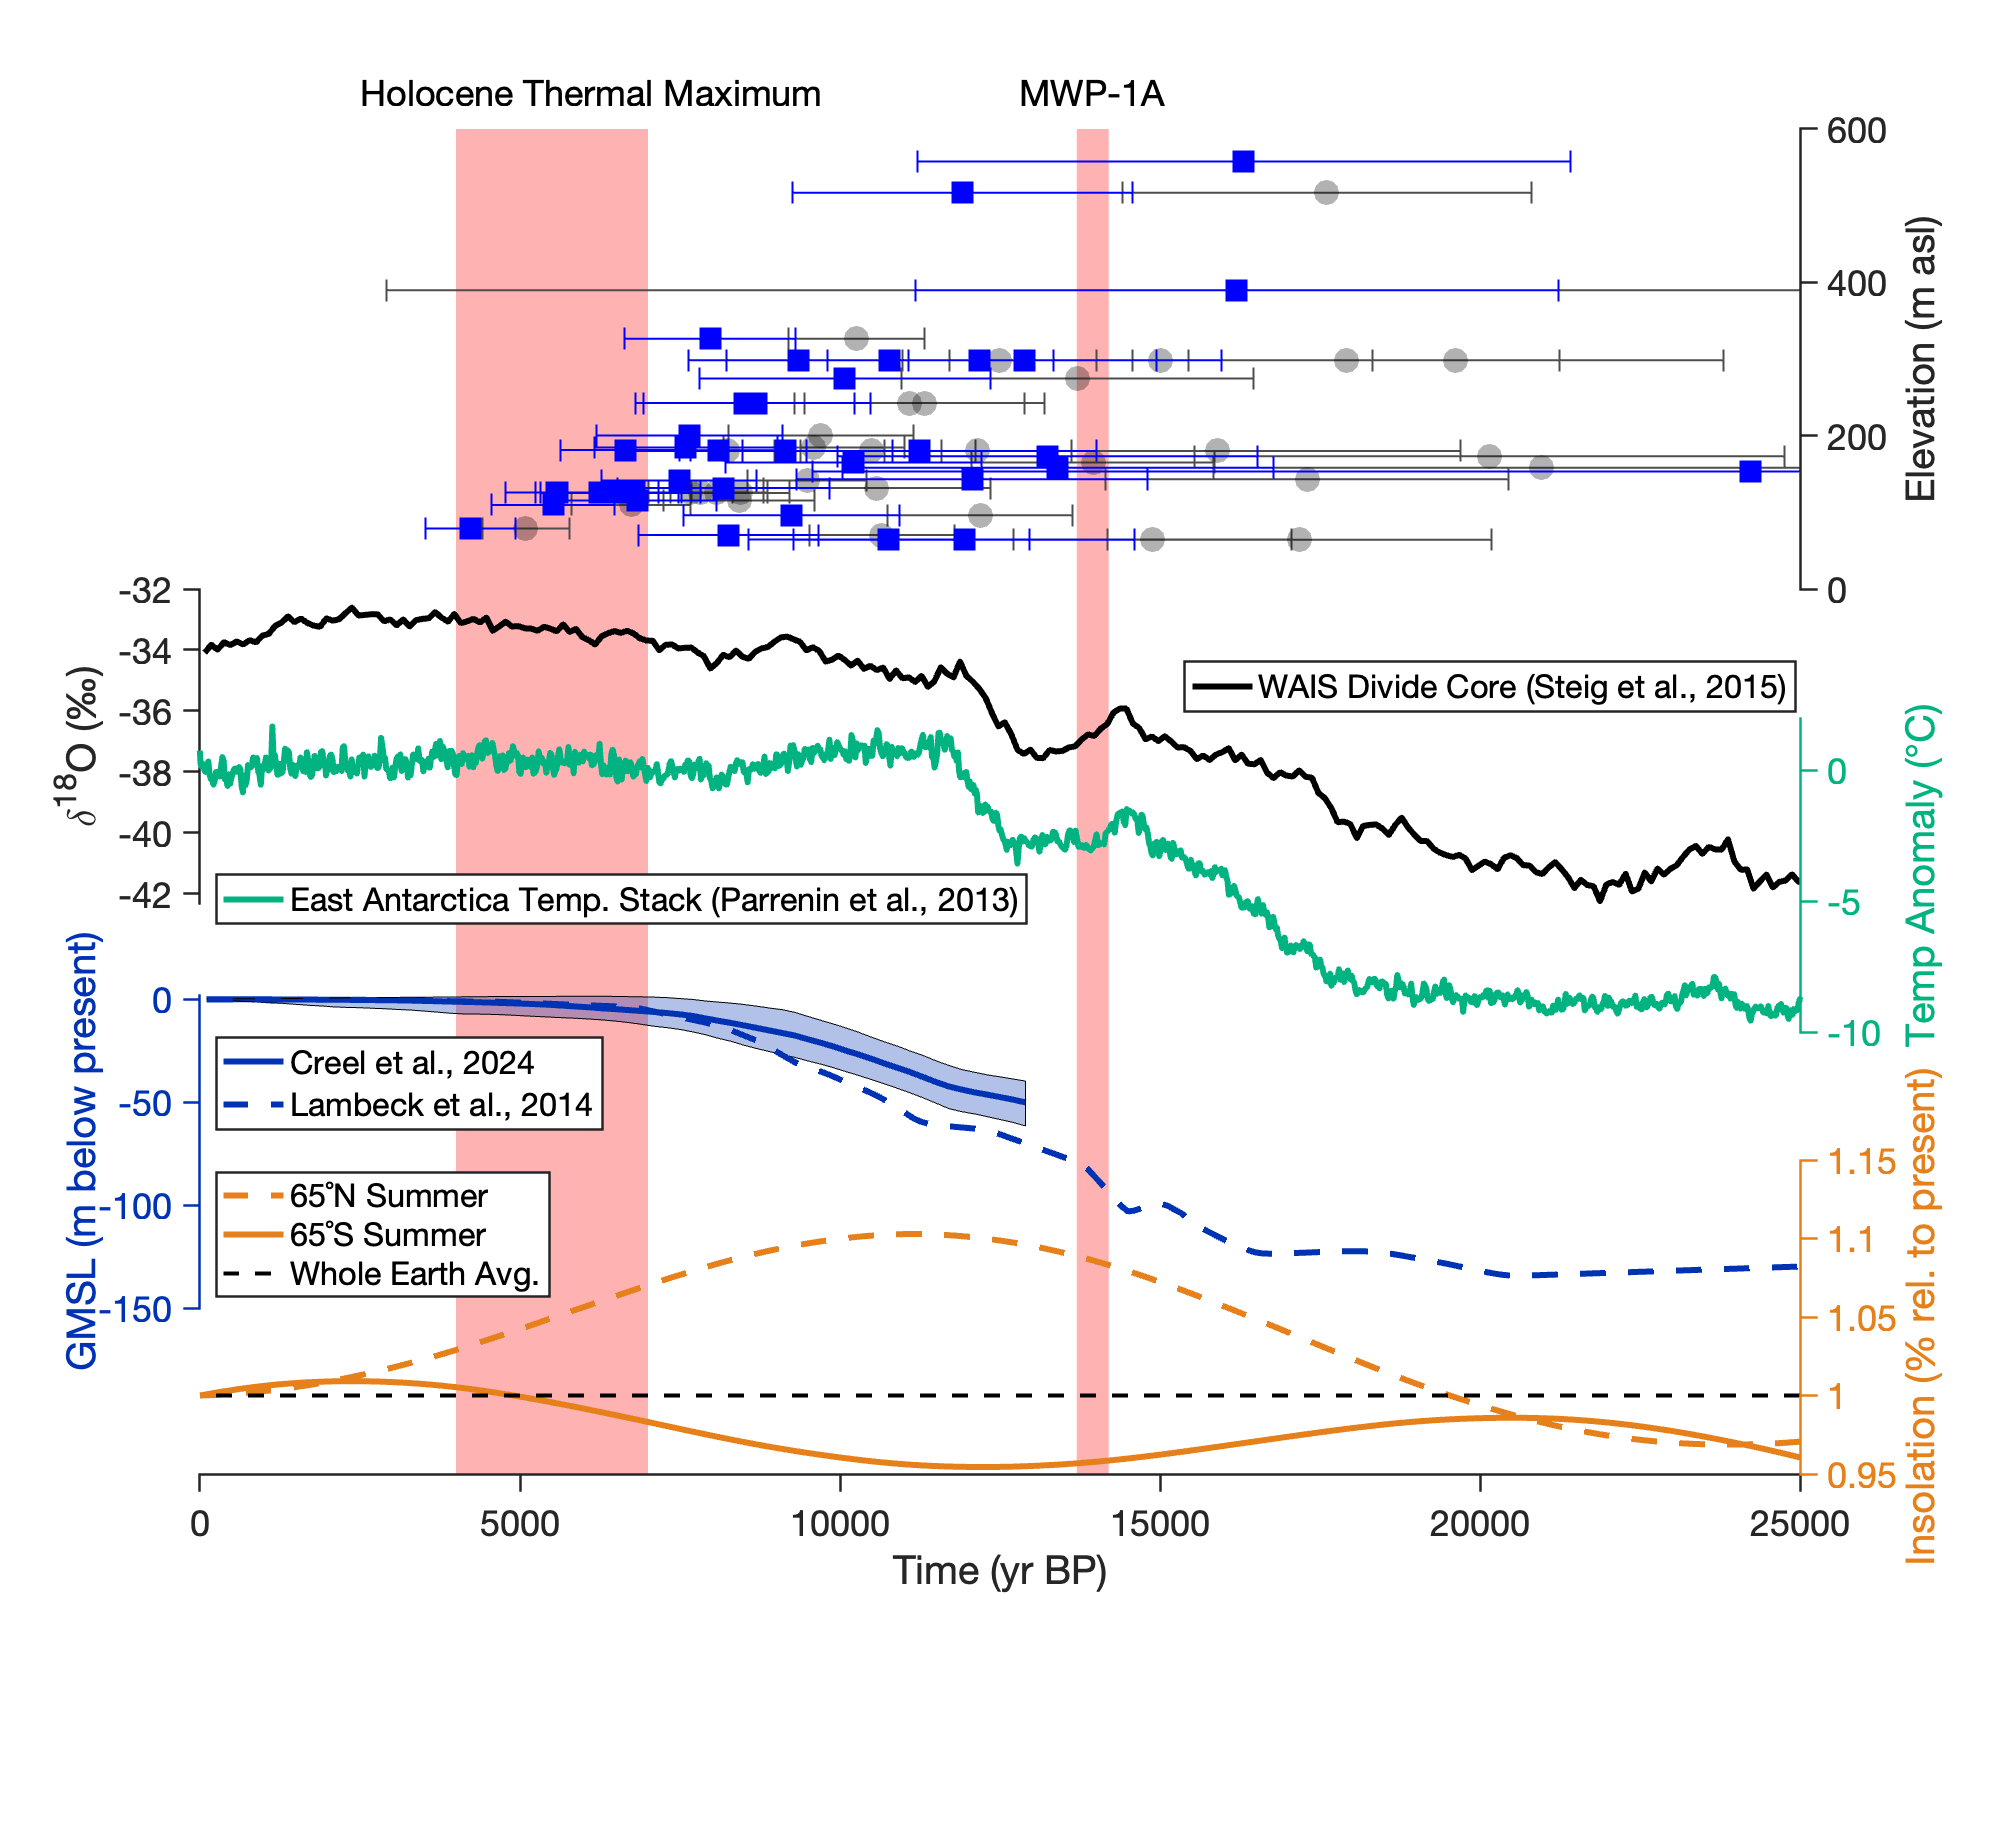

%Plot the same as the main figure but with only a single site at a time
set(0,'DefaultFigureVisible','on');
set(0,'DefaultFigureWindowStyle','normal');   % not docked

fig = figure('Units','pixels','Position',[100 100 1000 1000],'Color','w');

left = 0.1; width = 0.8; h = 0.17;
b1 = 0.98 - 0.3;
b2 = b1 - (h + 0);
b3 = b2 - (h - 0.1);
b4 = b3 - (h - 0.02);
b5 = b4 - (h - 0.08);

ax1 = axes('Position',[left b1 width 0.25], 'Box','off', 'Layer','top'); hold(ax1,'on')
ax2 = axes('Position',[left b2 width h], 'Box','off', 'Layer','top'); hold(ax2,'on')
ax3 = axes('Position',[left b3 width h], 'Box','off', 'Layer','top'); hold(ax3,'on')
ax4 = axes('Position',[left b4 width h], 'Box','off', 'Layer','top'); hold(ax4,'on')
ax5 = axes('Position',[left b5 width h], 'Box','off', 'Layer','top'); hold(ax5,'on')

axes_arr = [ax1 ax2 ax3 ax4 ax5];

%% ---------- ax1 ----------
errorbar(ax1, tam.orig_age, tam.elev, ...
        tam.orig_unc, tam.orig_unc, ...
        'horizontal','LineStyle','none', 'LineWidth', 1, 'Color', [0.3 0.3 0.3 0.4], 'CapSize',10);
scatter(ax1, tam.orig_age,  tam.elev, 160, 'k', 'filled', 'Marker','o', 'MarkerFaceAlpha',0.3);
errorbar(ax1, tam.calib_age, tam.elev, ...
        tam.calib_unc, tam.calib_unc, ...
        'horizontal','LineStyle','none', 'LineWidth', 1, 'Color','b', 'CapSize',10);
scatter(ax1, tam.calib_age, tam.elev, 200, 'b', 'filled', 'Marker','s', 'DisplayName','Trans-Antarctic Mountains');
ylabel(ax1,'Elevation (m asl)');

%% ---------- ax2 ----------
% δ18O on ax2
cla(ax2); hold(ax2,'on');
plot(ax2, clim_data.waisO18.age, clim_data.waisO18.oxy, 'k-', 'LineWidth',3, 'DisplayName', 'WAIS Divide Core (Steig et al., 2015)');
ylabel(ax2,'\delta^{18}O (‰)','Interpreter','tex');
set(ax2,'YAxisLocation','left','YLim',[-42.3 -32], ...
        'TickDir','out','LineWidth',1.25,'FontName','Helvetica', ...
        'Color','none','PositionConstraint','innerposition');
legend(ax2, 'location', [0.598,0.614845021037868,0.293,0.025])

%% ---------- ax3 ----------
ax3_1 = plot(ax3, clim_data.EATA.age, clim_data.EATA.TA, 'Color',[0 0.7 0.5], 'LineWidth',3, 'DisplayName', 'East Antarctica Temp. Stack (Parrenin et al., 2013)');
%scatter(ax3, 19625, -2, 400, 'MarkerFaceColor', [0.3 0.3 0.3], 'MarkerEdgeColor','none');
%scatter(ax3, 12885, -2, 400, 'MarkerFaceColor', 'b', 'MarkerEdgeColor','none');
ylim(ax3, [-10 2]);
ax3.YColor = [0 0.7 0.5];  % color of y-axis and ticks
ax3.YLabel.Color = [0 0.7 0.5];  % color of the y-axis label
ylabel(ax3,'Temp Anomaly (°C)'); yticks([-10 -8 -6 -4 -2 0 1]);
legend(ax3, [ax3_1], 'location', [0.108,0.49945652173913,0.405,0.025])

%% ---------- ax4 ----------
ax4_1 = plot(ax4, clim_data.creelSLR.age,  clim_data.creelSLR.mid, 'Color',[0 0.2 0.7], 'LineWidth', 3, 'DisplayName', 'Creel et al., 2024');
fill(ax4, [ clim_data.creelSLR.age; flipud( clim_data.creelSLR.age)], [ clim_data.creelSLR.lowunc; flipud( clim_data.creelSLR.highunc)], [0 0.2 0.7], 'FaceAlpha', 0.3)
ax4_2 = plot(ax4, clim_data.lambeckSLR.age, clim_data.lambeckSLR.SLR, 'Color',[0 0.2 0.7], 'LineWidth', 3, 'LineStyle', '--','DisplayName', 'Lambeck et al., 2014');
ylabel(ax4,'GMSL (m below present)');
ylim(ax4,[-150 2]);
ax4.YColor = [0 0.2 0.7];  % color of y-axis and ticks
ax4.YLabel.Color = [0 0.2 0.7];  % color of the y-axis label
yticks([-150 -100 -50 0])
legend(ax4, [ax4_1 ax4_2], 'location', [0.108166666666667,0.389003623188406,0.193,0.046195652173913])

%% ---------- ax5 ----------
plot(ax5, clim_data.solin65n.age, clim_data.solin65n.insolref, 'LineWidth',3, 'Color', [0.9 0.5 0.1], 'LineStyle', '--', 'DisplayName', '65˚N Summer');
plot(ax5, clim_data.solin65s.age, clim_data.solin65s.insolref, 'LineWidth',3, 'Color', [0.9 0.5 0.1], 'DisplayName', '65˚S Summer');
plot(ax5, clim_data.solinavg.age, clim_data.solinavg.insolref, 'k--', 'LineWidth',2, 'DisplayName', 'Whole Earth Avg.');
ylabel(ax5,'Insolation (% rel. to present)', 'HorizontalAlignment', 'center');
ylim(ax5,[0.95 1.15]);
yticks([0.95 1 1.05 1.1 1.15])
ax5.YColor = [0.9 0.5 0.1];  % color of y-axis and ticks
ax5.YLabel.Color = [0.9 0.5 0.1];  % color of the y-axis label
xticks([0 5000 10000 15000 20000 25000])
ax5.XAxis.Exponent = 0; xlabel(ax5,'Time (yr BP)');
legend(ax5, 'location', 'northwest')


%% ---------- shared x & formatting ----------
linkaxes(axes_arr,'x');
set([ax1 ax2 ax3 ax4 ax5], 'FontSize',18, 'FontName','Helvetica', ...
    'TickDir','out', 'LineWidth',1.25, 'Color','none');
set([ax1 ax2 ax3 ax4], 'XColor','none','XTick',[]);
xlim([0 25000]);

% y-axis sides (both δ18O and CO2 stay on left)
set([ax1 ax3 ax5],'YAxisLocation','right');
set([ax2 ax4],'YAxisLocation','left');

%% ---------- y-label spacing (restore clean layout) ----------
for ax = [ax2 ax4]
    ax.YLabel.Units = 'normalized'; p = ax.YLabel.Position; p(1) = -0.06; ax.YLabel.Position = p;
end
for ax = [ax1 ax3 ax5]
    ax.YLabel.Units = 'normalized'; p = ax.YLabel.Position; p(1) = 1.06;  ax.YLabel.Position = p;
end


%
%% ---------- background axis for manual-height bands ----------
% Decide exactly which vertical region should show the bands:
Ytop = ax1.Position(2) + ax1.Position(4);   % top of top panel you want covered
Ybot = ax5.Position(2);                     % bottom of lowest panel to cover
bandAx = axes('Position',[left Ybot width (Ytop - Ybot)], ...
    'Color','none','HitTest','off','HandleVisibility','off', ...
    'XLim',[0 25000],'YLim',[0 1], 'XTick',[], 'YTick',[], ...
    'XColor','none','YColor','none','Layer','bottom');

% --- Manually assign the vertical size of each band ---
% y0,y1 are fractions of the bandAx height (0 = bottom, 1 = top)
span_all = [0 1];

bands = [ 4000  7000;
         13700 14200];
cols  = [1 0 0; 1 0 0];
alpha_main = 0.30;

for b = 1:size(bands,1)
    x0 = bands(b,1); x1 = bands(b,2);
    y0y1 = span_all;
    patch(bandAx,[x0 x1 x1 x0],[y0y1(1) y0y1(1) y0y1(2) y0y1(2)], ...
          cols(b,:), 'FaceAlpha',alpha_main, 'EdgeColor','none');
end

% keep behind data and lock x with the other axes
linkaxes([axes_arr bandAx],'x');
% move the entire background axis behind all other axes
uistack(bandAx, 'bottom');

% labels
yl1 = ylim(ax1);
text(ax1,12800,yl1(2)*1.08,'MWP-1A','FontSize',18,'FontName','Helvetica','Clipping','off');
text(ax1, 2500,yl1(2)*1.08,'Holocene Thermal Maximum','FontSize',18,'FontName','Helvetica','Clipping','off');

fig = gcf;

%Turn on to save a high-resolution figure
%print(fig, 'cliamtecomparecalib_CCR.png', '-dpng', '-r600')